# Benchmarking stable multivariate lesion symptom mapping against conventional multivariate lesion symptom mapping

This tutorial demonstrates how to perform stable multivariate lesion symptom mapping, comparing it to more conventional multivariate lesion symptom mapping. In both approaches, we use a linear SVM (as implemented in matlab's statistics and machine learning toolbox, which you will need to follow this live code/notebook) to predict some deficit. Here, we will predict aphasia severity using the Aphasia Recovery Cohort (ARC), a large database of chronic stroke patients with aphasia that our lab has recently made publicly available. 

The difference between the two approaches we'll look at is that stable multivariate lesion symptom mapping adds a nested feature selection step, retaining only features that are stable for building a model to predict deficits.

## So what is lesion symptom mapping?

Lesion symptom mapping (LSM) is an approach to studying brain-behavior relationships that seeks to link the brain areas in which there is damage in a group of patients (e.g., strokes) to some deficit. The main strength of LSM compared to alternative approaches is that it permits causal inference. That is, with most other neuroimaging techniques for studying brain-behavior relationships (e.g., fMRI), the relationship that is observed is correlative. For example, say that we are interested in understanding which brain regions are involved in language. We can take a group of stroke patients and have them perform a naming task. We can then look at their patterns of blood flow to identify regions in which patients with greater language impairment show less blood flow. While this would tell us something about the areas involved in language, not all of these areas are guaranteed to be *necessary* for language. In other words, some of these area may support language without being so essential that damage to this region would impinge on language function. 

## How is lesion symptom mapping performed?

In traditional LSM, we loop through all of our voxels and in each voxel perform a univariate test. Because we treat voxels independently, LSM is often described as being a "mass univariate analysis". In each voxel, we separate patients with damage and patients without damage. This allows us to then perform some statistical test (e.g., think t-test) to determine if the subgroup of patients with damage at that particular location tend to show a stronger deficit. 

LSM can also be performed regionally. This helps assuage concerns about multiple comparison correction because an atlas can be used as a prior for reducing the number of features in the dataset.

## What is multivariate lesion symptom mapping (MLSM) and why bother to do it?

In multivariate lesion symptom mapping (MLSM), we try to predict the deficit using a model that simultaneously considers data from across the entire brain. So instead of separating patients with damage to a location and patients without damage to a location, we build a regression model to predict patient deficits from damage across the entire brain. What advantages does this confer? 

- Brain regions work in concert and MLSM considers damage across the entire brain to capture more complex patterns. For example, damage to a white matter tract can cause atrophy in the brain regions that it connects. This kind of disconnection may even be the underlying cause of a certain deficit. Under this scenario, we may see the same network of brain regions lesioned together in patients with worse deficits. However, we are also likely to see patients with damage to only some regions within the same network and these patients may exhibit weak or nonexistent deficits (e.g., because the tract was preserved but the lesion happened to affect some of the grey matter in the network). If our model is not explicitly considering the possibility that the deficit might result from damage to the whole network *together*, then it may only find weak associations between damage to each of the regions in the network and the deficit under study. Worse yet, it may suggest that each region contributes independently to the deficit, fundamentally misinterpreting the underlying pattern. You can also imagine a scenario outside of the disconnection theme, where two brain regions need to be damaged together to produce a deficit.

- MLSM does not just map simple interactions, but can also consider higher order interactions, additive effects and nonlinear relationships. For example, there may be some threshold of damage to a region of the brain that always results in a deficit. In other words, if say more than 20% of a certain region is damaged, no matter where, that amount of "lesion load" marks the point after which we always see a more severe deficit. In a case like this, looking at regional lesion load as a function of the deficit may look more like a log function than a linear function. As an alternative example, consider that partial damage to Broca's area may be insufficient to produce severe language deficits, which would also result in a nonlinear function. It may also be the case that  

- The emphasis on predicting new unseen data in MLSM builds validation into the analysis pipeline. Understanding whether your findings generalize to new data helps inform whether the results can be replicated. Neuroimaging has a replication problem that can be less visible compared to other fields because the cost associated with collecting new data is much higher. In clinical neuroimaging this issue is compounded by the difficult and slow process of identifying and recruiting patients. While sample sizes in clinical neuroimaging studies are increasing, unfortunately they are still quite small (Szucs & Ioannidis, 2020).

## But *why* is it that MLSM can work better than alternative univariate methods?

You might be thinking--why bother with MLSM, which typically uses machine learning, when you can just build a simple ordinary least squares regression model and include lower/higher-level interaction terms and explicitly model nonlinear functions. You can even test such a regression model on out-of-sample data to evaluate its predictive capacity. Well, including all of these terms explodes the number of features in your model, requiring a truly massive number of samples to effectively estimate model coefficients for prediction. 

MLSM works around this problem by introducing some mechanism for regularization (they can vary based on the type of model selected). This refers to the process of finding the right penalty for model complexity that serves to minimize model error in a way that adapts to the unique characteristics of a dataset (i.e., amount of signal to noise features, samples, etc). Typically, this involves testing many different values that work to control complexity on some out-of-sample data to find the values that produce the lowest model error. Regularization effectively acts to inject more bias into models in order to reduce the variance of the predictions, which can be advantageous for making more accurate predictions.

## Evaluating feature stability can result in more robust MLSM models

We've talked about how MLSM can identify more complex patterns in lesion data by better handling high dimensional feature spaces. However, the regularization strategy in MSLM is not a panacea and can fail. Let's unpack why this is the case.

- In the face of many redudnant features, succesful regularization will tend to favor simpler models, which means excluding the kinds of complex relationships that MLSM models bring to the table for lesion mapping

- When there are many redundant features or noise, especially in a high dimensional space (e.g., neuroimaging), getting regularization to be succesful in the first place is difficult. Thus, models may still consider complex relationships but many of them might be spurious and not generalize, tanking model performance. This is arguably a worse scenario than (1)

- Even if regularization is succesful, assignment of feature important can be inconsistent. When faced with multiple features that contain common predictive information, most algorithms will either favor one feature in this set over the others, or treat correlated features in counterintuive ways that dilute feature importance. For example, lasso selects one of many correlated variables while ridge regression adjusts the weights of correlated features together, which can result in scanarios where a group of correlated features may have low weights despite each being highly predictive of the response variable. In SVM's, the same penalty term as ridge regression is used and similar scenarios can crop up. Even in random forests, feature dilation can be observed.

- Provided enough feature redundancy or noise in the data, the preference for specific features in machine learning models models may shift, reflecting sensitivity to random variations in training data and noise

Arguably, MLSM models are only as informative as the weights that they learn. Here, we test whether identifying more reliable features for MLSM results in better models. What do we mean by better? 

- The models assign feature weights more consistently across different partitions of the data

- The models generalize better to unseen data (models that pick out more reliable patterns may pick out more generalizable patterns)

- The models pick out more complex patterns (in line with the point of performing MLSM in the first place)

## Stable multivariate lesion symptom mapping (sMLSM)

Neuroimaging datasets are particularly suscpetible to the issues that can make MLSM models learn unstable feature weights. We start with a high dimensional dataset. Even when we bin our data using an atlas, our feature space remains enormous because MLSM models aim to map higher order interactions and nonlinear relationships alongside main effects. At the same time, we have a massive amount of multicolinearity because proximal regions are more likely to be damaged together due to vasculature. This means we are working with many features that are either outright redundant, or at least difficult to distinguish for models because they are highly correlated. Finally, we are working with a large number of noisy features. That can include features corrupted by noise (e.g., suboptimal registration in more complex anatomy, suboptimal hand drawn lesion masks, imaging artifacts) but also features that are meaningful, but unrrelated to the deficit we wish to map. While we expect the contribution of large networks to a deficit as discussed above, we don't expect *all* networks to necessarily contribute in a significant way. 

Our solution to this problem is stable multivariate lesion symptom mapping (sMLSM). The approach is quite simple. Before building our model for predicting the deficit, we perturb our dataset hundreds of times to understand which features can be selected consistently by a feature selection algorithm of our choosing, generating a stable set of features for further modeling. Using the framework of stability selection, we can even use this process to set an upper bound on the number of false positives in the set of stable features (a per-family or per-comparison error rate). Using these stable features, we can then build a second model to predict patient deficits. Critically, we test the model on independent data. 

We see stability selection less as a feature discovery method and more as a way of removing features that are difficult to model. In this way, limited model resources are directed at exploiting as much signal as possible rather than learning distinctions between features that may not be as meaningful to the task.

## The tutorial

The point of this tutorial is to test whether sMLSM outperforms MLSM (see sections above for how we define "better" in this context). To this end, we add stability selection to the standard MLSM pipeline. In MLSM, models are trained and tuned in a nested fashion. Here, we use 10 outer folds for defining training and test datasets. Each of these 10 training datasets is further split into 4-folds for tuning and validation. Our sMLSM pipeline inserts stability selection before model tuning. That is, for each outer fold training dataset, we perform stability selection to identify reliable features. These features are then used to tune and test models. Note, test data is independent from the data we use for feature selection so there is no leakage there. However, inner training data for tuning overlaps with the data used for feature selection. We mitigate overfitting in this context by subsampling the dataset hundreds of times. By collapsing over relatively more models than if we introduced a third loop in the CV scheme, this approach can dilute the influence of noisy data or outliers. Finally, we repeat the entire CV scheme 11 times to get a sense of how partitioning noise impacts performance.

How do we know either MLSM or sMLSM models are any good? We benchmark them against a third model, one that only has access to lesion size and not lesion location. We also do some permutation testing for model significance. All of the models use SVR, but stability selection relies on elastic net for simplicity. The input to all models includes lesion size to account for the effect of this variable in MLSM and sMLSM. Otherwise, inputs to MLSM and sMLSM are vectors reflecting the proportion of each region within an atlas that is damaged in a participant. 

# Getting started: loading in data for sMLSM, checking dependencies, and setting up a cross validation scheme for model tuning and test

We will be working with the Aphasia Recovery Cohort (ARC), a publicly available database of chronic stroke patients with aphasia. You can find this database here: [https://openneuro.org/datasets/ds004512/versions/2.0.0.](https://openneuro.org/datasets/ds004512/versions/2.0.0.) Note, though, the data that is publicly availabe is in something we call "native" space. That just means that each persons' brain is stored just as it was collected, reflecting their unique brain anatomy, shape, etc. In neuroimaging, the fact that everyone's brain is completely different is an enormous challange for analysis. Even though every one of us has, for instance, a Heschl's gyrus, which is a specific anatomical sturcture of the brain that is responsible for early auditory processing, every persons' Heschl's gyrus looks a little different. What's more is that even if two people had an identical heschl's gyrus, the way they happened to have been lying in the MRI while data was collected means that their gyri might be in slightly different locations in space. Thus, conventional neuroimaging analysis involves a preprocessing step where we take every one of our participants' brains and stretch, shear, and rotate them to fit a template that is representative of everyone's anatomy--a template of brain structure. We will work with a preprocessed version of this dataset.

## Dependencies

Before we continue, please make sure:

- You have the matlab statistics and machine learning toolbox installed (we need this for SVM)

- You have the stabSel package and its directories added to your path

- You have downloaded the data we will use (e.g., prepARC.mat) and placed it in the stabSel directory: https://drive.google.com/drive/folders/1oFEGYgq4LzDBSYd0zzgDPvbGRGOapWkt?usp=sharing

- To replicate our way of generating non-brain figures, which rely on a function called quickScatter.m, you will also need to download our correlogram package: [https://github.com/alexteghipco/Correlogram](https://github.com/alexteghipco/Correlogram)

- To replicate our way of generating brain figures and export results to nifti files, you will need to download brainSurfer: [https://github.com/alexteghipco/brainSurfer](https://github.com/alexteghipco/brainSurfer)

The code below will try to check that you have all of the dependencies available for this tutorial. Make sure to run this code because it sets up our base directory in case you are *not* in the stabSel directory...

% Check presence of stats toolbox...
if license('test','Statistics_Toolbox')
    disp('Found the statistics toolbox! We can now perform SVM')
else
    error('You can run stabSel, but we cannot build our predictive models without the statistics toolbox from MATLAB, please install before proceeding...')
end

Found the statistics toolbox! We can now perform SVM


% Try to look for stabSel in your path...
ss = which('stabSel.m');

% Confirm stabSel.m is in your path and add
% subdirectories to the path if you have not done that yet...
if isempty(ss)
    error('stabSel is not in your path!! Please add it to your path before proceeding...')
else
    disp('Found stabSel! This code should work just fine!')
    [ss,~,~] = fileparts(ss);
    addpath(genpath(ss))
end

Found stabSel! This code should work just fine!


% Let's also check if you have quickScatter installed (part of the
% correlogram package)
bd = which('quickScatter.m');
if isempty(bd)
    warning('Non-brain figure generation will throw an error! Please download the correlogram repository')
else
    disp('Found correlogram! Figure generation should work..')
    [bd,~,~] = fileparts(bd);
    addpath(genpath(bd))
end

Found correlogram! Figure generation should work..


% And finally, check for brainSurfer...
bd = which('brainSurfer.mlapp');
if isempty(bd)
    warning('Brain figure generation and nifti export will throw an error! Please download the brainSurfer repository')
else
    disp('Found brainSurfer! Figure generation should work..')
    [bd,~,~] = fileparts(bd);
    addpath(genpath(bd))
end

Found brainSurfer! Figure generation should work..


## Loading in the organized data we will be working with

To explain how LSM works, we will first load in all of our brain data. Now, I have nicely prepared everything for you in a .mat file called prepARC.mat which is what you downloaded above. So first, let's import that into our workspace.

try
    load([fullfile(ss, 'prepARC.mat')])
    disp('Loaded JHU atlas data (% damage within ROIs) succesfully!')
catch
    error('You either did not download the lesion data linked above or did not place it in the stabSel directory!')
end

Loaded JHU atlas data (% damage within ROIs) succesfully!


## An example of how to load in your own brain data for sMLSM by visualizing the atlases we will be working with

You may have noticed that prepARC.m has a matrix called 'les', which continas our lesion data. We really only need this data for this tutorial, but let's say you have nifti files you would like to load in to analyze with stabSel. The code below will show you how to import nifti data into matlab for analysis.

Let's start off with a very simple example where we load a single file. The stabSel toolbox comes with a function that will help you load in all the nifti files in a single folder on your computer, using either spm, freesurfer, or matlab's imaging toolbox--whichever you happen to have installed (it will look for all 3 in a sequence). 

We are going to start off analyzing regional damage according to the JHU atlas so we'll take this opportunity to visualize this atlas. The stabSel toolbox comes packaged withi it (in ./LSMAtlases/jhu). Note, the first input to brainLoad is the path to a folder that contains **all** the .nii *and *.nii.gz files that you would like to import. The second input to brainLoad is a path to a specific file which we can use as a mask. That is, only voxels that are nonzero in the mask will be pulled from each .nii and .nii.gz file being imported into matlab. We don't really care about masking our atlas so we can leave the second input as an empty variable for this exercise. When an input is left empty like this, a GUI will pop up for you to select either a folder (input 1) and/or a file (input 2). In our case, we can just hit cancel when this GUI pops up, which will let brainLoad know that we aren't intending to use a mask.

[~,jhuAtlas,~,initSz] = brainLoad(fullfile(ss,'LSMAtlases','jhu'),[]);

Please select your brain mask nifti file. All nonzero values in the mask will be treated as areas of the brain you want to keep.
No loadable mask supplied Proceeding without the mask...if this is not expected behavior please make sure spm_read_vols or load_nifti or niftiread is in your path
Working on file 1 of 1
File is: jhu.nii.gz


Now we can visualize the JHU atlas using matlab's montage function, plotting the jhuAtlas variable. One wrinkle to brainLoad is that it assumes all your nifti files are the same shape. So if your nifti files are in different template spaces, for example, this will throw an error. Another thing about brainLoad is that it vectorizes the brain data. As long as we did not use a mask, we can reshape our brain data back into a 3D matrix for functions that might expect this shape (as shown below). In a forthcoming update, brainLoad will also output variables that will let us reshape our brain data back into its 3D matrix form even when we use a mask.

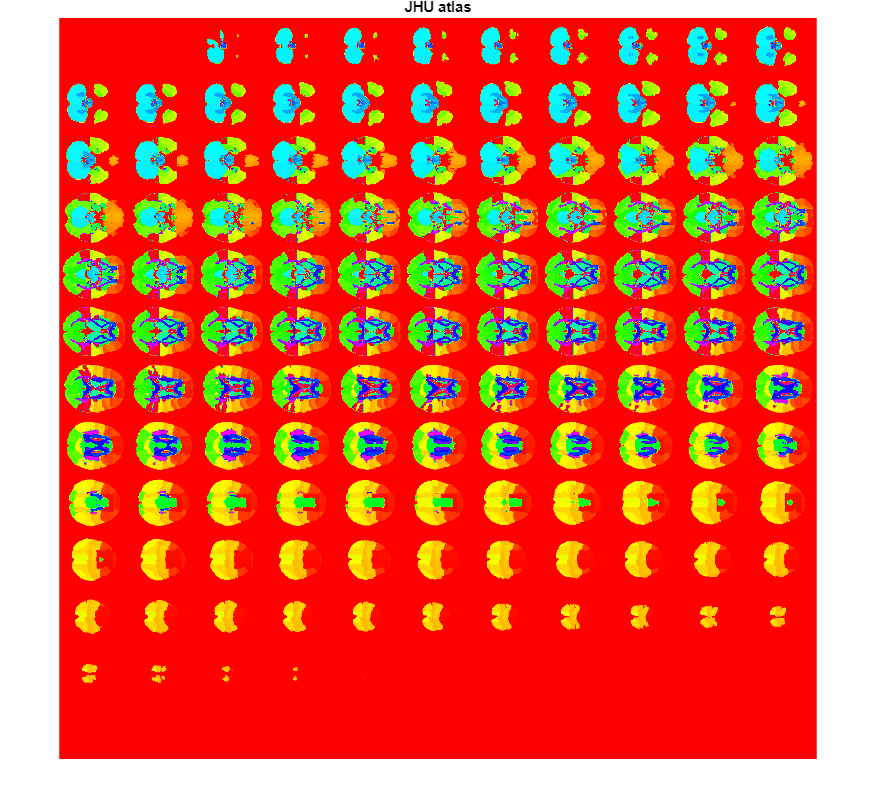

jhuAtlas = reshape(jhuAtlas,initSz); % initSz contains the shape of the nifti file before vectorization so we can reshape it back into its original form
montage(jhuAtlas,'DisplayRange',[0 max(jhuAtlas(:))]); % the montage function requires the imaging toolbox, and we specify the limits based on the data (i.e., largest ROI value)
colormap(hsv) % this is a colormap to avoid boring greyscale but you can use whatever you would like
title('JHU atlas'); % a title for the montage

You can also load in multiple files at once, like so. Later on in the analysis we will use a multi-resolution atlas and we can load in that atlas now for inspection.

[fileNames,multiresAtlas,~,initSz] = brainLoad(fullfile(ss,'LSMAtlases','multires'),[]);

Please select your brain mask nifti file. All nonzero values in the mask will be treated as areas of the brain you want to keep.
Trying to load using matlabs niftiread.m
Did not work! Trying to load using freesurfers load_nifti.m
Did not work! Trying to load using spm load_nifti.m


No loadable mask supplied Proceeding without the mask...
Working on file 1 of 10
File is: Schaefer2018_1000Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 2 of 10
File is: Schaefer2018_100Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 3 of 10
File is: Schaefer2018_200Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 4 of 10
File is: Schaefer2018_300Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 5 of 10
File is: Schaefer2018_400Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 6 of 10
File is: Schaefer2018_500Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 7 of 10
File is: Schaefer2018_600Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 8 

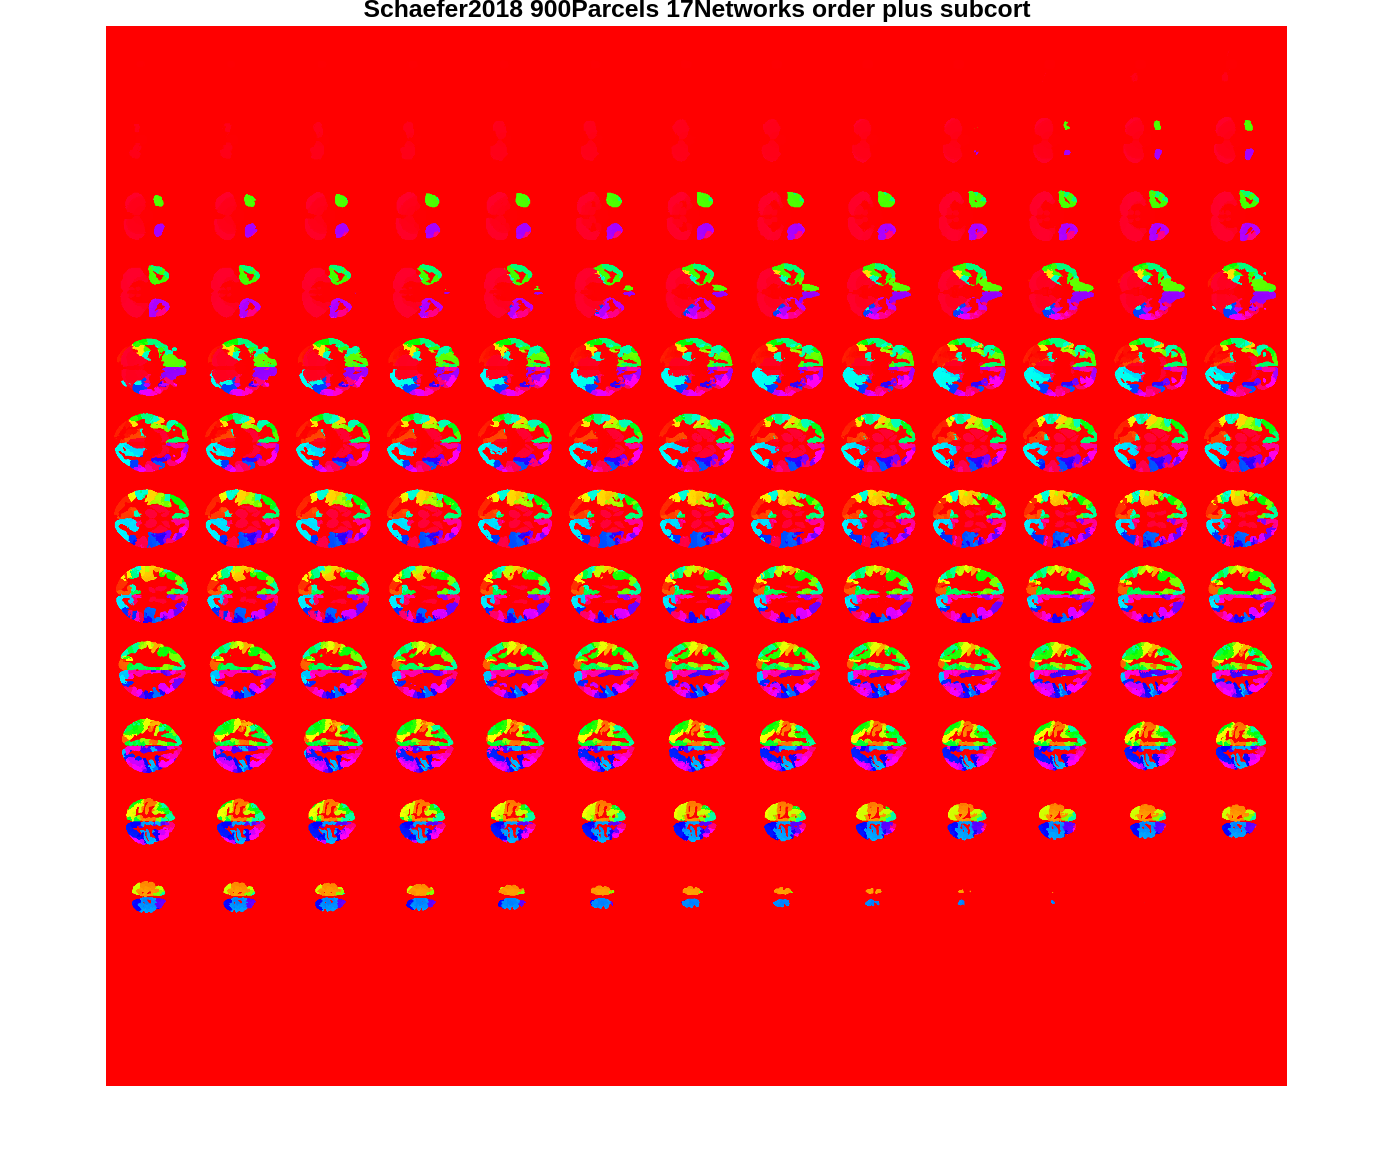

fileNames = extractBefore(strrep(fileNames,'_',' '),'.nii'); % here we are changing the filenames so matlab does not misinterpret underscores as subscripts for figure titles (we also remove the extension of the file)
for i = 1:length(fileNames) % we loop over files and visualize each one in a sequence. you should be able to play back the whole sequence at a slower rate in the live code
    tmp = reshape(multiresAtlas(:,i),initSz); % reshape the data as before into a 3D matrix
    ctmp = hsv(max(tmp(:))); % we need to predefine a colormap because for whatever reason, MATLAB will not update the colormap for a figure that gets overwritten multiple times inside live code
    montage(tmp,double(ctmp),'DisplayRange',[0 max(tmp(:))]); % identical montage call but here we specify the colormap values
    title(fileNames{i});
end

Note, the data we analyze with stabSel should be vectorized so we would not need to reshape its output usually, this is only necessary for the montage visualization (or for exporting files). For stabSel, I would recommend using a mask so that you have a smaller matrix to analyze.

#### A small note on how we visualize the atlas in the manuscript

Above, we are rendering atlases without too much care in volume space just to get a sense of the data that we are working with. Please take a look at brainSurfer to convert atlases to surface space--you can do this by just loading in the atlas through the GUI and making sure to specify that your map contains multiple ROIs. A JHU atlas projection comes with the package and we show in later analyses how to load up this rendering without using the brainSurfer GUI and write in your own values for each ROI (i.e., based on some regional analysis results).

## Setting up inputs for analysis (excluding subjects and ROIs)

Let's start analyzing the JHU atlas-binned lesion data. For now, we will remove the atlas files we experimented with in loading nifti files for stabSel since the data has already been organized for us in the .mat files we loaded in. We will then remove subjects with lesions that do not overlap with our specific atlas (e.g., you can imagine that some atlases won't have the same coverage, like subcortical regions, etc), and remove regions in the atlas that show no damage in our sample or damage in a small proportion of participants. If you are running your own data.

clearvars -except X y z labs
% X is our predictor matrix but we have one matrix for each atlas
% our response variable is y, or aphasia severity. For now, we keep one per atlas because it is possible for atlases to have a different number of subjects based on the way we are processing the data
% lesion volume is z

% remove empty participants (no lesion overlap with any ROI in atlas)
tor = []; % this is the vector of participants to remove that we will track
for j = 1:size(X,2)
    if sum(X(:,j)) == 0
        tor = [tor; j];
    end
end
% we need to make sure to remove participants across all our variables
y(tor) = [];
z(tor) = [];
X(:,tor) = [];

% now find participants with missing behavior
tor = find(isnan(y));
y(tor) = [];
z(tor) = [];
X(:,tor) = [];

% find ROIs with no damage in any participant
tor = [];
for j = 1:size(X,1)
    if sum(X(j,:)) == 0
        tor = [tor; j];
    end
end
X(tor,:) = [];
labs(tor,:) = [];

% now remove rois represented by fewer than 10 participants
clear rid2 rid
for j = 1:size(X,1)
    rid2(j) = length(find(X(j,:) ~= 0));
end
rid = find(rid2 <= 10);
X(rid,:) = [];
labs(rid,:) = [];

X = X';
clear rid rid2 tor beh j les 

## Setting up a cross-validation scheme

We now need to set up a cross validation scheme for our analysis. This will ensure that when we build our stable multivariate lesion symptom mapping (sMLSM) and standard multivariate lesion symptom mapping models (MLSM), we will always have external data for testing model accuracy. 

To set this up, we will use matlab's cvpartition function. We will use this to setup 10 outer folds and will repeat cross validation 11 times. One trick we'll use is to pretend we are doing classification so that we can stratify our folds by lesion size. This is so that we can ensure each training dataset gets consistent exposure to lesions of varying size (at least in a crude way, based on categories we will define from lesion size).

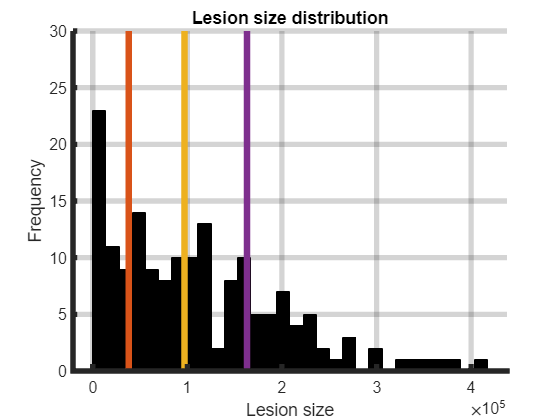

% Create lesion size quantiles from our data
q = quantile(z,[0.25 0.5 0.75]); 
cat = zeros(1,length(z));
cat(z <= q(1)) = 1; %1st lesion size category (<= 1st quartile)
cat(z > q(1) & z <= q(2)) = 2; % 2nd lesion size category (> 1st quartile and <= median)
cat(z > q(2) & z <= q(3)) = 3; % 3rd lesion size category (> median and <= 3rd quartile)
cat(z > q(3)) = 4; % 4th lesion size category (> 3rd quartile)

for j = 1:11 % we will make 11 random partitions stratified by our lesion quartiles...
    c{j} = cvpartition(cat,"KFold",10,"Stratify",true);
end
save('JHU_lesion_categories.mat','cat')

% this is a simple plot of the quartiles...you can see each group is about
% the same in size
figure; histogram(z,30,'FaceAlpha',1,'FaceColor',[0 0 0]);
hold on
plot([q(1) q(1)],[0 30],'LineWidth',5);
plot([q(2) q(2)],[0 30],'LineWidth',5);
plot([q(3) q(3)],[0 30],'LineWidth',5);
set(gcf,'color','w');set(gca,'FontSize',12); set(gca,'LineWidth',4); box off; grid on; set(gca,'GridAlpha',0.2);
title('Lesion size distribution')
ylabel('Frequency')
xlabel('Lesion size')

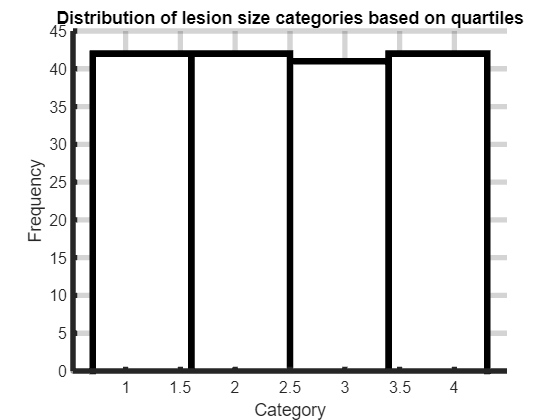

figure; histogram(cat,4,'FaceAlpha',1,'FaceColor',[1 1 1],'LineWidth',5);
title('Distribution of lesion size categories based on quartiles')
set(gcf,'color','w');set(gca,'FontSize',12); set(gca,'LineWidth',4); box off; grid on; set(gca,'GridAlpha',0.2);
ylabel('Frequency')
xlabel('Category')

# Preliminary analysis: a quick introduction to stability selection for sMLSM

## Stable multivariate lesions symptom mapping leverages stability selection and requires setting some hyperparameters

Let's start by building some preliminary stable multivariate lesion symptom mapping (sMLSM) models since these will be the main emphasis of the tutorial. What's important to point out for now is that in sMLSM, we use a specific kind of feature selection: stability selection. This framework for feature selection is very flexible but has some parameters that must be chosen.

Here, we will focus on a very simple implementation of this framework, in line with the original studies that proposed it. This means the following: 

- In sMLSM, we will create hundreds of perturbed datasets using subsamples (other options are available but this for simplicity and to be faithful to the original stability selection study, we stick with subsampling)

- For each perturbed dataset, we will perform feature selection using an algorithm of our choosing. Again, many options are available. But here, we will use an algorithm very close to what was used wtih the original stability selection proposal: elastic net. While the original approach was applied to lasso, we use elastic net because it should be more consistent (e.g., when features are correlated it will **not** tend to randomly select one of multiple correlated features like lasso)

- On each perturbed dataset, we select some number of features (e.g., half of the entire feature set)

- We will tally up the number of times each feature was selected across perturbed datasets to generate stability scores (i.e., the proportion of datasets in which a feature was selected). Note, we do this for every hyperparameter in a specified range for elastic net and then take the highest stability score across hyperparameters. For elastic net, we use a reasonable default set of hyperparameters (more on that later).

- We will then find a "stable" set of features by identifying a threshold for stability scores that attempts to ensure an upper bound on the number of false positives in the stable set. We can get this threshold provided we know the number of false positives we would like to place an upper bound on, and the average number of features selected across perturbed datasets by our feature selection technique. Here, we will force elastic net to select about half of the features in our dataset by tracking the order in which features enter the model. 

- The number of false positives is mainly relevant in the context of the stable set size. We would probably prefer to have 1 false positive in a stable set of 100 features than 20 features. Thus, we tend to conceptualize the per family error rate in what we call the stable false discovery ratio (sFDR), which is just the proportion of false positives to the stable set size.

As you can see from above, the main hyperparameters that we have to choose for sMLSM are: 1) the hyperparameter sequences to use for our feature selection algorithm, 2) the number of features to select for each perturbed dataset, 3) the number of false positives we are comfortable with in our stable set. 

Although some studies have suggested points (1) and (2) should not substantially influence the results, we agree with other authors that have pointed out they may be influential and deserve further investigation. Given that testing all of these settings dramatically increases analysis run time and complexity, here, we start by using conventional or reasonable defaults for (1) and (2), and test how (3) influences sMLSM model performance. If sMLSM is robust, it should outperform MLSM consistently across a relatively wide range of settings for the number of false positives. 

Let's start by doing a preliminary analysis where we establish whether stability selection can provide consistent measures of feature stability across runs. Our goal will be to test whether increasing the number of perturbed datasets from 25 to 500 will make any difference on the variability of these feature stability scores. 

Let's get straight into it! Here, we will start with an arbitrary but reasonable number of false positives and use a measly 25 perturbations of our data. We'll look at feature stability score consistency across 5 runs. Please note, your outputs willl be the same but with two exceptions. First, we have updated the PCER that is displayed by stabSel to provide an alternative anchor for "significance". Previously, PCER was computed generically by dividing the number of false positives by the total number of features. Now, we try to take into account the multiple testing nature of stability selection by dividing the number of false positives by the number of features selected on average across all resampled datasets. If you find the traditional PCER more informative for your purposes, this is easy to compute--just divide the PFER displayed in the command window by stabSel by the number of features in your dataset. Note, we have also removed what we previously called the "FDR-like p-value". We will reintroduce this sometime down the line but do not want to cause confusion with what we now call the stable false discovery ratio, which in many ways, is a better apprioximation of something like FDR.

for i = 1:5
    disp(['------WORKING ON REPEAT: ' num2str(i) ' of ' num2str(5)])
    [fk{i},~,fscmx(:,i),~,~,~,~,~,~,~,~,empMaxVars{i},~,~,~] = stabSel(X,y,'selAlgo','en',...
        'samType','subsample','rep',25,'compPars',false,'numFalsePos',1,'maxVars',...
        size(X,2)/2,'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.05:1],'fixMax',true,'prop',0.5,'verbose',true);
end

------WORKING ON REPEAT: 1 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 11.2776
Probability threshold for features to enter stable set was calculated to be: 1.3367
Number of features in the s

------WORKING ON REPEAT: 2 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 11.6193
Probability threshold for features to enter stable set was calculated to be: 1.3882
Number of features in the s

------WORKING ON REPEAT: 3 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 11.3404
Probability threshold for features to enter stable set was calculated to be: 1.3461
Number of features in the s

------WORKING ON REPEAT: 4 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 10.9735
Probability threshold for features to enter stable set was calculated to be: 1.2922
Number of features in the s

------WORKING ON REPEAT: 5 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 11.4297
Probability threshold for features to enter stable set was calculated to be: 1.3595
Number of features in the s

Now let's see how consistent our feature selection probabilities are (i.e., assignment of stability scores) in a relatively crude but intuitive way--by correlating probabilities across repeats

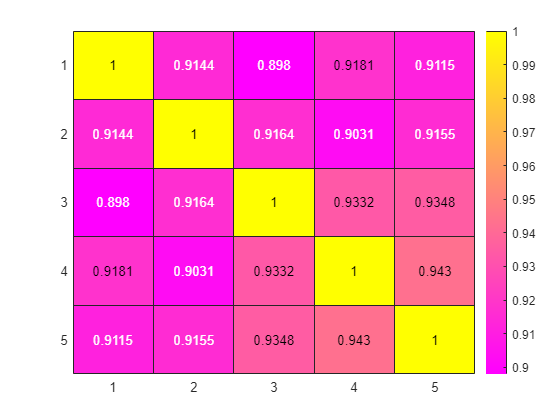

[r,~] = corr(fscmx);
figure; h = heatmap(r);
colormap('spring')

Looks like we're getting some decently consistent feature stability assignments! About 25 resamples is what has been originally recommended to use with stability selection. But can we make this better? Let's try a more reasonable number of resamples...this will take maybe 30 minutes to run...

for i = 1:5
    disp(['------WORKING ON REPEAT: ' num2str(i) ' of ' num2str(5)])
    [fk2{i},~,fscmx2(:,i),~,~,~,~,~,~,~,~,empMaxVar2s{i},~,~,~] = stabSel(X,y,'selAlgo','en',...
        'samType','subsample','rep',500,'compPars',false,'numFalsePos',1,'maxVars',...
        size(X,2)/2,'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.05:1],'fixMax',true,'prop',0.5,'verbose',true);
end

------WORKING ON REPEAT: 1 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 500
Working on subsample 2 of 500
Working on subsample 3 of 500
Working on subsample 4 of 500
Working on subsample 5 of 500
Working on subsample 6 of 500
Working on subsample 7 of 500
Working on subsample 8 of 500
Working on subsample 9 of 500
Working on subsample 10 of 500
Working on subsample 11 of 500
Working on subsample 12 of 500
Working on subsample 13 of 500
Working on subsample 14 of 500
Working on subsample 15 of 500
Working on subsample 16 of 500
Working on subsample 17 of 500
Working on subsample 18 of 500
Working on subsample 19 of 500
Working on subsample 20 of 500
Working on subsample 21 of 500
Working on subsample 22 of 500
Working on subsample 23 of 500
Working on subsample 24 of 500
Working on subsample 25 of 500
Working on subsample 26 of 500
Working on subsample 27 of 500
Working on subsample 28 of 500
Working on subsample 29 of 500
Working on subsample 30 of 500
Working on subsample

------WORKING ON REPEAT: 2 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 500
Working on subsample 2 of 500
Working on subsample 3 of 500
Working on subsample 4 of 500
Working on subsample 5 of 500
Working on subsample 6 of 500
Working on subsample 7 of 500
Working on subsample 8 of 500
Working on subsample 9 of 500
Working on subsample 10 of 500
Working on subsample 11 of 500
Working on subsample 12 of 500
Working on subsample 13 of 500
Working on subsample 14 of 500
Working on subsample 15 of 500
Working on subsample 16 of 500
Working on subsample 17 of 500
Working on subsample 18 of 500
Working on subsample 19 of 500
Working on subsample 20 of 500
Working on subsample 21 of 500
Working on subsample 22 of 500
Working on subsample 23 of 500
Working on subsample 24 of 500
Working on subsample 25 of 500
Working on subsample 26 of 500
Working on subsample 27 of 500
Working on subsample 28 of 500
Working on subsample 29 of 500
Working on subsample 30 of 500
Working on subsample

------WORKING ON REPEAT: 3 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 500
Working on subsample 2 of 500
Working on subsample 3 of 500
Working on subsample 4 of 500
Working on subsample 5 of 500
Working on subsample 6 of 500
Working on subsample 7 of 500
Working on subsample 8 of 500
Working on subsample 9 of 500
Working on subsample 10 of 500
Working on subsample 11 of 500
Working on subsample 12 of 500
Working on subsample 13 of 500
Working on subsample 14 of 500
Working on subsample 15 of 500
Working on subsample 16 of 500
Working on subsample 17 of 500
Working on subsample 18 of 500
Working on subsample 19 of 500
Working on subsample 20 of 500
Working on subsample 21 of 500
Working on subsample 22 of 500
Working on subsample 23 of 500
Working on subsample 24 of 500
Working on subsample 25 of 500
Working on subsample 26 of 500
Working on subsample 27 of 500
Working on subsample 28 of 500
Working on subsample 29 of 500
Working on subsample 30 of 500
Working on subsample

------WORKING ON REPEAT: 4 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 500
Working on subsample 2 of 500
Working on subsample 3 of 500
Working on subsample 4 of 500
Working on subsample 5 of 500
Working on subsample 6 of 500
Working on subsample 7 of 500
Working on subsample 8 of 500
Working on subsample 9 of 500
Working on subsample 10 of 500
Working on subsample 11 of 500
Working on subsample 12 of 500
Working on subsample 13 of 500
Working on subsample 14 of 500
Working on subsample 15 of 500
Working on subsample 16 of 500
Working on subsample 17 of 500
Working on subsample 18 of 500
Working on subsample 19 of 500
Working on subsample 20 of 500
Working on subsample 21 of 500
Working on subsample 22 of 500
Working on subsample 23 of 500
Working on subsample 24 of 500
Working on subsample 25 of 500
Working on subsample 26 of 500
Working on subsample 27 of 500
Working on subsample 28 of 500
Working on subsample 29 of 500
Working on subsample 30 of 500
Working on subsample

------WORKING ON REPEAT: 5 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 500
Working on subsample 2 of 500
Working on subsample 3 of 500
Working on subsample 4 of 500
Working on subsample 5 of 500
Working on subsample 6 of 500
Working on subsample 7 of 500
Working on subsample 8 of 500
Working on subsample 9 of 500
Working on subsample 10 of 500
Working on subsample 11 of 500
Working on subsample 12 of 500
Working on subsample 13 of 500
Working on subsample 14 of 500
Working on subsample 15 of 500
Working on subsample 16 of 500
Working on subsample 17 of 500
Working on subsample 18 of 500
Working on subsample 19 of 500
Working on subsample 20 of 500
Working on subsample 21 of 500
Working on subsample 22 of 500
Working on subsample 23 of 500
Working on subsample 24 of 500
Working on subsample 25 of 500
Working on subsample 26 of 500
Working on subsample 27 of 500
Working on subsample 28 of 500
Working on subsample 29 of 500
Working on subsample 30 of 500
Working on subsample

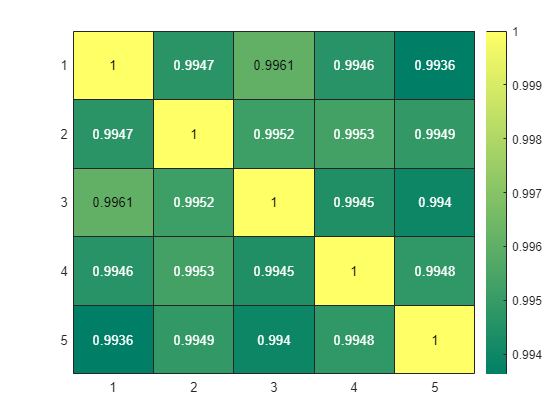

[r2,~] = corr(fscmx2);
figure; h = heatmap(r2);
colormap('summer')

I know that took some time to run but it was worth it! You should now see correlations of ~0.99+. 

## Manipulating stable set definition after running stabSel

If you looked at the documentation for stabSel you may have noticed that it automatically computes the stable set of features based on a preselected number of false positives we would like to maintain in the stable set, the PFER. The problem with this approach is that you don't know ahead of time how large the stable set will be, so your preselected PFER may be disproportionate to the resulting stable set, the threshold for which is defined using the PFER. If the PFER is too low, it may force the stability threshold to be so high that the stable set is empty. Alternatively, a handful of features might enter the stable set, but we might expect a high proportion of them to be false positives. 

We can solve this issue after running stabSel because once we have the stability scores, we can vary the PFER, recompute the stability threshold, and measure the proportion of the stable set that may be false positives. We call this proportion the stable set false discovery ratio (sFDR) to highlight the intuitive parallel to the False Discovery Rate (FDR), but emphasize that these are independent concepts. For example, the PFER basis of sFDR implies a higher stringency. 

Here is a snippet of code that allows you to change the stable set. Below, we will use it to show how the size of the stable set changes as we manipulate the number of false positives.

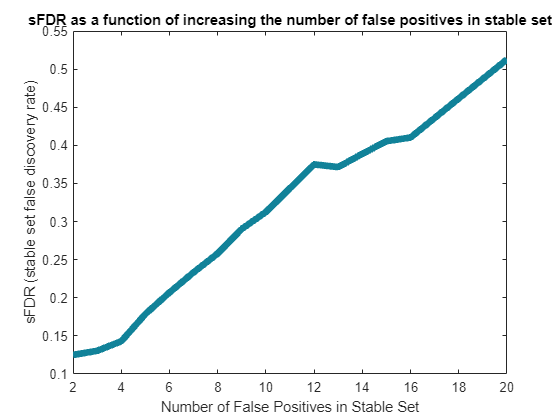

% now let's manipulate our number of false positives. To get an even more
% stable set of scores we will take the mean stability score over all our
% repeats
for i = 1:20
    % note we have left the formula on the next line but stabSel has a
    % function you can call to apply a new FPER threshold to a previous run
    % of stabSel (see recompStableFeats.m)
    t = ((((mean(cell2mat(empMaxVar2s)).^2)/size(X,2))/i)+1)/2; % formula for computing feature selection probability threshold given the average number of features selected across resampled datasets
    epfer(i,1) = i./length(find(mean(fscmx2,2) > t)); % if you took the indices of fscmx > t you would get the new stable set
    epferLen(i,1) = length(find(mean(fscmx2,2) > t));
end
figure; plot(epfer,'Color',[0.0667    0.5098    0.6000],'LineWidth',5);xlabel('Number of False Positives in Stable Set'); ylabel('sFDR (stable set false discovery rate)')
title('sFDR as a function of increasing the number of false positives in stable set')

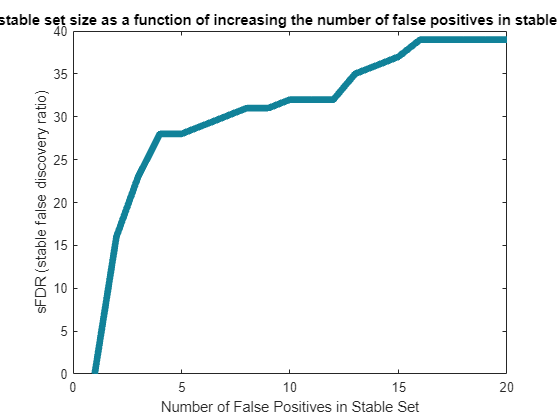

figure; plot(epferLen,'Color',[0.0667    0.5098    0.6000],'LineWidth',5);xlabel('Number of False Positives in Stable Set'); ylabel('sFDR (stable false discovery ratio)')
title('stable set size as a function of increasing the number of false positives in stable set')

# Analysis 1: Now that you've gotten the hang of stability selection, let's actually run stable multivariate lesion symptom mapping on the JHU atlas

We will dissociate the portion of sMLSM where we perform feature selection and the portion where we build our MLSM model. We do this so that the process becomes conceptually easier to grasp and so that it's easier to save out portions of the pipeline if something goes wrong (note, this will take quite some time to run!!!). If you prefer, you can nest stability selection and MLSM in one single for loop and save the outputs on every training dataset that is being fit.

for r = 1:length(c)
    for i = 1:c{r}.NumTestSets
        disp(['Working on outer fold:' num2str(i)])
        [fkRaw{r}{i},~,probRaw{r}{i},~,~,~,~,~,~,~,~,empMaxVarsRaw{r}{i},~,~,~] = stabSel(X(training(c{r},i),:),y(training(c{r},i)),'selAlgo','en',...
            'samType','subsample','rep',500,'compPars',false,'numFalsePos',3,'maxVars',30,'keepScores',false,...
            'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.05:1],'fixMax',true,'prop',0.5,'verbose',true);
    end
    try
        save('JHU_stabSel_results.mat');
    catch
        save('JHU_stabSel_results.mat','-v7.3');
    end
end

Now let's build a MLSM model using our stable features. One thing we will experiment with is understanding how the sMLSM model performance changes when we manipulate the number of false positives that we are comfortable with. We will also compare these models to a baseline model that just uses lesion size. 

tot = 30; % this is the max number of false positives we will test: 1...tot
for r = 1:length(fkRaw) % loop over repeats of CV...
    disp(['Working on repeat:' num2str(r) ' of ' num2str(length(fkRaw))])
    for n = 1:tot % loop over sequence of false positives
        for i = 1:length(fkRaw{r}) % test set

            % first define your new stable set...
            fkfin{i}{r}{n} = recompStableFeats(probRaw{r}{i},empMaxVarsRaw{r}{i},n);

            % now train a lesion size only model--note, we set this to
            % use fitlm here for speed but you are welcome to comment
            % this line out and uncomment lines 196-213 to perform SVM
            % instead. When deciding which to use, for what it is
            % worth, we did run both on one repeat and found no
            % difference in error magnitude
            if n == 1
                bmdlLV{i} = fitlm(z(training(c{r},i)),y(training(c{r},i)),'RobustOpts','on');
            end

            % first, define hyperparameters for lesion model. Note, we
            % do not tune KernelScale as matlab's heuristic is quite
            % good at finding a decent value. We also tune the kernel
            % function for SVM (linear, gaussian, polynomial 2nd order).
            % if n == 1 % we do this so we are not constantly rerunning these models when we don't have to
            %     hype = hyperparameters('fitrsvm',z(training(c{r},i)),y(training(c{r},i)));
            %     hype(2).Optimize = false;
            %     hype(1).Range = [1.0000e-03 800];
            %     hype(4).Optimize = true;
            %
            %     % train lesion size only model
            %     bmdlLV = fitrsvm([z(training(c{r},i))],y(training(c{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
            %         'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
            %         'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');
            %
            %     % get lesion size model predictions
            %     yhatLV(test(c{r},i),r) = predict(bmdlLV,z(test(c{r},i)));
            %
            %     % also get training dataset-based naive predictions (i.e.,
            %     % mean of training dataset is the prediction)
            %     guessLV(test(c{r},i),r) = mean(y(training(c{r},i)));
            % end

            % define hyperparameters for sMLSM (same as above, see line 199)
            hype = hyperparameters('fitrsvm',[X(training(c{r},i),fkfin{i}{r}{n}) z(training(c{r},i))],y(training(c{r},i)));
            hype(2).Optimize = false;
            hype(1).Range = [1.0000e-03 800];
            hype(4).Optimize = true;

            % Now we need to train the SVM on stable features plus lesion
            % size (sMLSM model). You can increase the number of
            % evaluations here for bayesian optimization and this
            % should improve model performance a tiny bit. Note, hype options override other arguments (e.g., KernelFunction,linear)
            bmdlAF{i,r,n} = fitrsvm([X(training(c{r},i),fkfin{i}{r}{n}) z(training(c{r},i))],y(training(c{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');
            % Get sMLSM model predictions
            yhatAF(test(c{r},i),r,n) = predict(bmdlAF{i,r,n},[X(test(c{r},i),fkfin{i}{r}{n}) z(test(c{r},i))]);

            % now get one last control model--here we use all the
            % features (MLSM)
            if n == 1
                hype = hyperparameters('fitrsvm',[X(training(c{r},i),:) z(training(c{r},i))], y(training(c{r},i)));
                hype(2).Optimize = false;
                hype(1).Range = [1.0000e-03 800];
                hype(4).Optimize = true;

                % Now we need to run a SVM on *all* features plus lesion size
                bmdlAFc{r,i} = fitrsvm([X(training(c{r},i),:) z(training(c{r},i))],y(training(c{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                    'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                    'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');
                yhatAFc(test(c{r},i),r) = predict(bmdlAFc{r,i},[X(test(c{r},i),:) z(test(c{r},i))]);
            end
        end

        % compute various performance measures for each MLSM model (we
        % do this after each loop of CV so the predictions are stacked
        % across test datasets)
        if n == 1
            [AFc_corr(r,1),AFc_corrp(r,1)] = corr(yhatAFc(:,r),y);
            AFc_mae(r,1) = mean(abs(y-yhatAFc(:,r)));
            AFc_mase(r,1) = AFc_mae(r,1) ./ mean(abs(y-guessLV(:,r)));
            AFc_ap(r,1) = (1-AFc_mase(r,1))*100;
        end

        % compute various performance measures for each sMLSM model
        [AF_corr(r,n),AF_corrp(r,n)] = corr(yhatAF(:,r,n),y);
        AF_mae(r,n) = mean(abs(y-yhatAF(:,r,n)));
        AF_mase(r,n) = AF_mae(r,n) ./ mean(abs(y-guessLV(:,r)));
        AF_ap(r,n) = (1-AF_mase(r,n))*100;
    end

    % compute various performance measures for the lesion size only model
    [lsz_corr(r,1),lsz_corrp(r,1)] = corr(yhatLV(:,r),y);
    lsz_mae(r,1) = mean(abs(y-yhatLV(:,r)));
    lsz_mase(r,1) = lsz_mae(r,1) ./ mean(abs(y-guessLV(:,r)));
    lsz_ap(r,1) = (1-lsz_mase(r,1))*100;
    try
        save('JHU_sMLSM_results.mat');
    catch
        save('JHU_sMLSM_results.mat','-v7.3');
    end
end
clear tot r n i bmdlLV hype  % cleanup stuff that we will not need

## Now let's plot model accuracies as a function of sFDR set for stability selection

% get mean and SEM for all models...
AFc_corr_m = mean(AFc_corr);
AFc_corr_sem = std(AFc_corr)./sqrt(length(AFc_corr));
AFc_ap_m = mean(AFc_ap);
AFc_ap_sem = std(AFc_ap)./sqrt(length(AFc_ap));
AF_corr_a = AF_corr; % here I was combining a few additional repeats run on a different computer which is why we redefine some variables...
AF_ap_a = AF_ap;

AF_corr_a_m = mean(AF_corr_a);
AF_ap_a_m = mean(AF_ap_a);
AF_corr_a_sem = std(AF_corr_a)./sqrt(length(AF_corr_a));
AF_ap_a_sem = std(AF_ap_a)./sqrt(length(AF_corr_a));

AF_corr_m = mean(AF_corr);
AF_ap_m = mean(AF_ap);

AF_corr_sem = std(AF_corr)./sqrt(length(AF_corr));
AF_ap_sem = std(AF_ap)./sqrt(length(AF_corr));

lsz_corr_m = mean(lsz_corr);
lsz_ap_m = mean(lsz_ap);

lsz_corr_sem = std(lsz_corr)./sqrt(length(lsz_corr));
lsz_ap_sem = std(lsz_ap)./sqrt(length(lsz_ap));

% Now compute stable set sizes, sFDR and PCER
for a = 1:length(fkRaw)
    disp(['Working on repeat: ' num2str(a) ' of ' num2str(length(fkRaw))])
    for n = 1:30
        for i = 1:length(fkRaw{a}) % test set
            nfk(a,i,n) = length(fkfin{i}{a}{n});
            ep(a,i,n) = n./nfk(a,i,n);
            ep2(a,i,n) = n./size(X,2);%(n/2)./nfk(a,i,n);
        end
    end
end

Working on repeat: 1 of 11
Working on repeat: 2 of 11
Working on repeat: 3 of 11
Working on repeat: 4 of 11
Working on repeat: 5 of 11
Working on repeat: 6 of 11
Working on repeat: 7 of 11
Working on repeat: 8 of 11
Working on repeat: 9 of 11
Working on repeat: 10 of 11
Working on repeat: 11 of 11


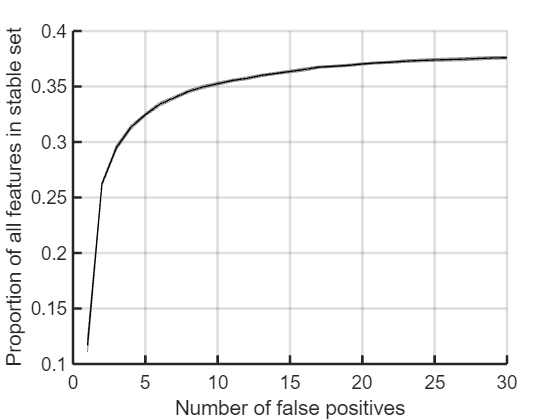

% fix stable set sizes of zero
id = find(isinf(ep));
ep(id) = NaN;
id = find(isinf(ep2));
ep2(id) = NaN;

% get mean and sem for sfdr, pcer, stable set size
nfk_m = squeeze(mean(mean(nfk,2,'omitnan'),1,'omitnan'))';
pfer_m = squeeze(mean(mean(ep,2,'omitnan'),1,'omitnan'))';
pcer_m = squeeze(mean(mean(ep2,2,'omitnan'),1,'omitnan'))';

nfk_sem = squeeze(std(mean(nfk,2,'omitnan'),[],1,'omitnan'))'./sqrt(size(squeeze(mean(nfk,2,'omitnan')),1));
pfer_sem = squeeze(std(mean(ep,2,'omitnan'),[],1,'omitnan'))'./sqrt(size(squeeze(mean(nfk,2,'omitnan')),1)); % this is sfdr
pcer_sem = squeeze(std(mean(ep2,2,'omitnan'),[],1,'omitnan'))'./sqrt(size(squeeze(mean(nfk,2,'omitnan')),1));

% plot of the number of features in the stable set...
tmp = nfk_m(1:30)./size(X,2);
tmp2 = nfk_sem./size(X,2);
figure; plt1 = shadedErrorBar([1:30],tmp,[tmp-tmp2; tmp+tmp2]);
box off; set(gcf,'color','w'); ax = gca; ax.LineWidth = 2; grid on; set(gca,'TickLength',[0.02 0.02]); set(gca,'FontSize',14)
xlabel('Number of false positives')
ylabel('Proportion of all features in stable set')

#### Now we should get "tuned" models. 

Because we saved out all the models, we can now compare the error for each number of false positives we used to build the model

tot = 30;
for r = 1:length(fkRaw) % repeats
    disp(['Working on repeat ' num2str(r) ' of ' num2str(length(fkRaw))])
    for i = 1:length(fkRaw{r}) % test set
        % for i, which n wins?'
        for n = 1:tot % extract model loss
            moderr(n,1) = bmdlAF{i,r,n}.HyperparameterOptimizationResults.MinEstimatedObjective;
            ep(i,r,n) = n./length(fkfin{i}{r}{n});
            epc(i,r,n) = n./size(X,2);
        end
        moderrw = moderr .* (1 + 0.002 .* [1:length(moderr)]'); % linearly weight the loss slightly to favor lower sFDR by favoring a smaller number of false positives. Note, we use this weighting across ALL analyses in our manuscript, including when testing other sample sizes and atlases
        [mv,nfpWinner(i,r)] = min(moderrw);
        epWinner(i,r) = nfpWinner(i,r)./length(fkfin{i}{r}{nfpWinner(i,r)});
        epcWinner(i,r) = nfpWinner(i,r)./size(X,2);
        yhatAFT(test(c{r},i),r) = predict(bmdlAF{i,r,nfpWinner(i,r)},[X(test(c{r},i),fkfin{i}{r}{nfpWinner(i,r)}) z(test(c{r},i))]);
    end
    [AF_corrT(r,1),AF_corrpT(r,1)] = corr(yhatAFT(:,r),y);
    AF_maeT(r,1) = mean(abs(y-yhatAFT(:,r)));
    AF_maseT(r,1) = AF_maeT(r,1) ./ mean(abs(y-guessLV(:,r)));
    AF_apT(r,1) = (1-AF_maseT(r,1))*100;
end

Working on repeat 1 of 11
Working on repeat 2 of 11
Working on repeat 3 of 11
Working on repeat 4 of 11
Working on repeat 5 of 11
Working on repeat 6 of 11
Working on repeat 7 of 11
Working on repeat 8 of 11
Working on repeat 9 of 11
Working on repeat 10 of 11
Working on repeat 11 of 11


AF_corrT_m = mean(AF_corrT);
AF_apT_m = mean(AF_apT);

AF_corrT_sem = std(AF_corrT)./length(AF_corrT);
AF_apT_sem = std(AF_apT)./length(AF_corrT);

#### Anf finally we can make the main plot! Model performance (y-axis) as a function of number of false positives (color)  and sFDR (x-axis)

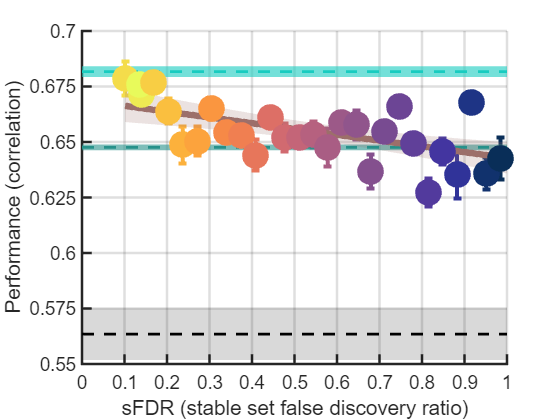

figure; plt1 = shadedErrorBar([0 1.1],[AFc_corr_m AFc_corr_m],repmat([AFc_corr_m-AFc_corr_sem AFc_corr_m+AFc_corr_sem]',1,2));
plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
hold on
plt2 = shadedErrorBar([0 1.1],[lsz_corr_m lsz_corr_m],repmat([lsz_corr_m-lsz_corr_sem lsz_corr_m+lsz_corr_sem]',1,2));
plt2.mainLine.LineWidth = 2;plt2.mainLine.LineStyle= '--';
plt2.edge(1).Visible = 'off';plt2.edge(2).Visible = 'off';
plt2.mainLine.Color =  [0.1490    0.5686    0.5412];
plt2.patch.FaceColor = plt2.mainLine.Color;
plt2.patch.FaceAlpha = 0.6;

plt3 = shadedErrorBar([0 1.1],[AF_corrT_m AF_corrT_m],repmat([AF_corrT_m-AF_corrT_sem AF_corrT_m+AF_corrT_sem]',1,2));
plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
plt3.patch.FaceColor = plt3.mainLine.Color;
plt3.patch.FaceAlpha = 0.6;

[parts] = quickScatter(AF_corr_m,pfer_m,'perfectY',false,'useWholeMap',true,'err',[AF_corr_sem; pfer_sem]','markerAlpha',1,'newFig',false);
parts.annot.Visible = 'off';set(gca,'FontSize',14)
ax = gca;
ax.XTick = [0:0.1:1];
xlim([0 1]);
ax.YTick = [0.55:0.025:0.7];
xlabel('sFDR (stable set false discovery ratio)')
ylabel('Performance (correlation)')

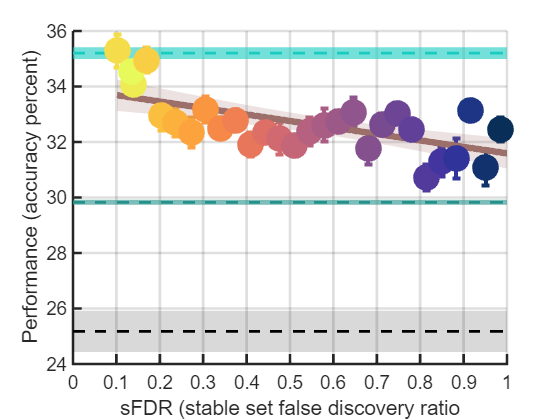

% ap
figure; plt1 = shadedErrorBar([0 1.1],[AFc_ap_m AFc_ap_m],repmat([AFc_ap_m-AFc_ap_sem AFc_ap_m+AFc_ap_sem]',1,2));
plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
hold on
plt2 = shadedErrorBar([0 1.1],[lsz_ap_m lsz_ap_m],repmat([lsz_ap_m-lsz_ap_sem lsz_ap_m+lsz_ap_sem]',1,2));
plt2.mainLine.LineWidth = 2;plt2.mainLine.LineStyle= '--';
plt2.edge(1).Visible = 'off';plt2.edge(2).Visible = 'off';
plt2.mainLine.Color =  [0.1490    0.5686    0.5412];
plt2.patch.FaceColor = plt2.mainLine.Color;
plt2.patch.FaceAlpha = 0.6;
plt3 = shadedErrorBar([0 1.1],[AF_apT_m AF_apT_m],repmat([AF_apT_m-AF_apT_sem AF_apT_m+AF_apT_sem]',1,2));
plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
plt3.patch.FaceColor = plt3.mainLine.Color;
plt3.patch.FaceAlpha = 0.6;
[parts] = quickScatter(AF_ap_m(1:30),pfer_m(1:30),'perfectY',false,'useWholeMap',true,'err',[AF_ap_sem(1:30); pfer_sem(1:30)]','markerAlpha',1,'newFig',false);
parts.annot.Visible = 'off';set(gca,'FontSize',14);
ax = gca;
ax.XTick = [0:0.1:1];
xlim([0 1]);
xlabel('sFDR (stable set false discovery ratio')
ylabel('Performance (accuracy percent)')

#### Evaluating tuning

It's also worth checking how the tuned models did...did they tend to converge towards a certain number of false positives? The scatter plots above would suggest they should trend towards a smaller number of false positives. Of course, the point of tuning the model is to allow more false positives if it improves the model based on out-of-sample errors, so despite the average results above, we still expect quite a few training datasets to favor a *relatively* larger number of false positives.

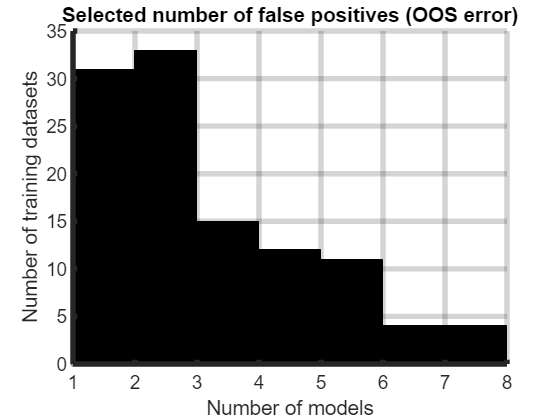

figure; histogram(nfpWinner(:),max(nfpWinner(:))-min(nfpWinner(:)),'FaceColor',[0 0 0],'FaceAlpha',1); grid on; box off; set(gcf,'color','w');set(gca,'FontSize',14); set(gca,'LineWidth',4); set(gca,'GridAlpha',0.2);
xlim([min(nfpWinner(:)) max(nfpWinner(:))]);
title('Selected number of false positives (OOS error)')
xlabel('Number of models')
ylabel('Number of training datasets')

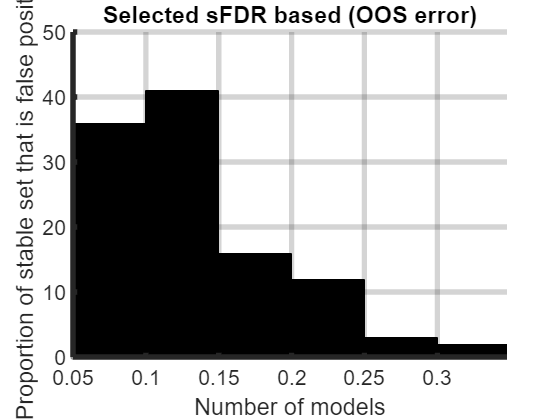

figure; histogram(epWinner(:),'FaceColor',[0 0 0],'FaceAlpha',1); grid on; box off; set(gcf,'color','w');set(gca,'FontSize',16); set(gca,'LineWidth',4); set(gca,'GridAlpha',0.2);
xlim([min(epWinner(:)) max(epWinner(:))]);
title('Selected sFDR based (OOS error)')
xlabel('Number of models')
ylabel('Proportion of stable set that is false positive')

In my results above, you can see a sharp decline in models for which an sFDR > 0.15 minimized out-of-sample errors. 

## Let's formally test for differences between each sMLSM model we've run and the MLSM and lesion size models

The idea is that we will concatenate all of our models' predictions across all repeats of CV. We will then test to see whether raw error (absolute) is higher for one model vs another across all predictions using a wilcoxon rank sum test. We will also correct for multiple comparisons in the process.

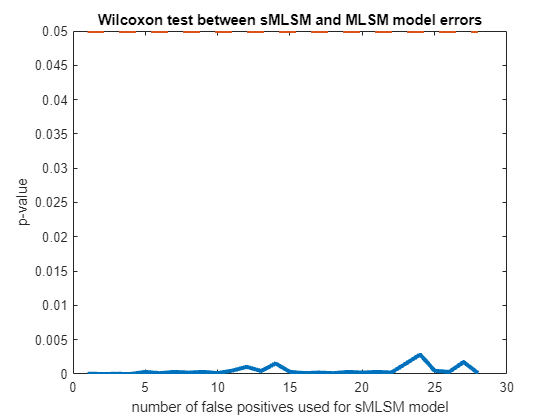

% reshape MLSM, tuned sMLSM and lesion volume models into one vector,
% stacking over repeats of CV. 
lvtmp = reshape(yhatLV,[size(yhatLV,1)*size(yhatLV,2),1]);
mlsmtmp = reshape(yhatAFc,[size(yhatAFc,1)*size(yhatAFc,2),1]);
smlsmtunetmp = reshape(yhatAFT,[size(yhatAFT,1)*size(yhatAFT,2),1]);
ytmp = repmat(y,size(yhatAFT,2),1); % also need to stack y so we can easily get errors with matrix subtraction

% we will perform a wilcoxon rank sum test because our distributions are
% not normal, but if you want, you can uncomment the code below to perform
% t-tests instead, they also show overall lower errors for sMLSM than
% lesion volume models across different number of false positives, but the
% effects are not quite as robust given violation of the normality
% assumption. 

% loop over sMLSM models which were not tuned (i.e., iteratively increasing
% number of false positives)
for i = 1:size(yhatAF,3)
    tmp = reshape(yhatAF(:,:,i),[size(yhatAF,1)*size(yhatAF,2),1]); % reshape as above
    [smlsmVsmlsm_wt_p(i,1),~,stats] = ranksum(abs(ytmp-tmp),abs(ytmp-mlsmtmp)); % test vs MLSM
    smlsmVsmlsm_wt_z(i,1) = stats.zval;

    [smlsmVslv_wt_p(i,1),~,stats] = ranksum(abs(ytmp-tmp),abs(ytmp-lvtmp)); % test vs lesion volume model
    smlsmVslv_wt_z(i,1) = stats.zval;

    % Uncomment this to perform t-tests instead and comment out the above
    % lines 
    % [~,smlsmVsmlsm_wt_p(i,1),~,stats] = ttest(abs(ytmp-tmp),abs(ytmp-mlsmtmp)); % test vs MLSM
    % smlsmVsmlsm_wt_z(i,1) = stats.tstat;
    % 
    % [~,smlsmVslv_wt_p(i,1),~,stats] = ttest(abs(ytmp-tmp),abs(ytmp-lvtmp)); % test vs lesion volume model
    % smlsmVslv_wt_z(i,1) = stats.tstat;
end


% here, we are testing for differences but using a corrected t-test for
% repeated cross-validation schemes (this accounts for dependencies between
% folds). To run, additionally download: https://github.com/alexteghipco/correctedKfoldTest
[tmpt(i,1),tmpp(i,1)] = corrttestcv(abs(yhatAFc-y),abs(yhatLV-y),c)

% tests for models that do not have multiple number of false positives:
% tuned sMLSM, MLSM, lesion volume
[smlsmtuneVslv_wt_p,~,stats] = ranksum(abs(ytmp-smlsmtunetmp),abs(ytmp-lvtmp));
smlsmtuneVslv_wt_z = stats.zval;
[smlsmtuneVsmlsm_wt_p,~,stats] = ranksum(abs(ytmp-smlsmtunetmp),abs(ytmp-mlsmtmp));
smlsmtuneVsmlsm_wt_z = stats.zval;

% now let's plot the results
smlsmVsmlsm_wt_pFDR = mafdr(smlsmVsmlsm_wt_p(1:28),'BHFDR',true); % note, we restrict to 28 here, because after that NFP, in our models, stability selection had as many false positives as there were items in the stable set
figure; plot(smlsmVsmlsm_wt_pFDR,'LineWidth',3)
hold on; plot([1 length(smlsmVsmlsm_wt_pFDR)],[0.05 0.05],'LineWidth',3,'LineStyle','--');
xlabel('number of false positives used for sMLSM model')
ylabel('p-value')
title('Wilcoxon test between sMLSM and MLSM model errors')

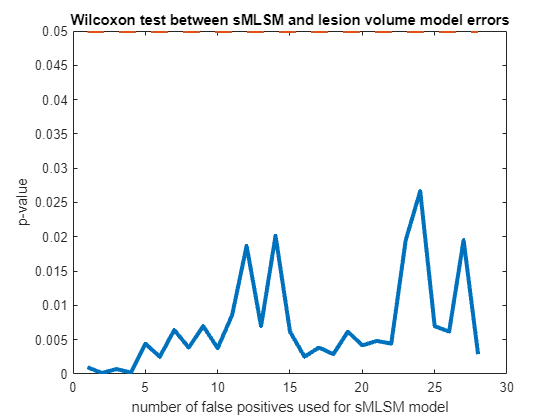

smlsmVslv_wt_pFDR = mafdr(smlsmVslv_wt_p(1:28),'BHFDR',true);
figure; plot(smlsmVslv_wt_pFDR,'LineWidth',3)
hold on; plot([1 length(smlsmVslv_wt_pFDR)],[0.05 0.05],'LineWidth',3,'LineStyle','--');
xlabel('number of false positives used for sMLSM model')
ylabel('p-value')
title('Wilcoxon test between sMLSM and lesion volume model errors')

## Scatter plots of each type of models' performance (as an ensemble)

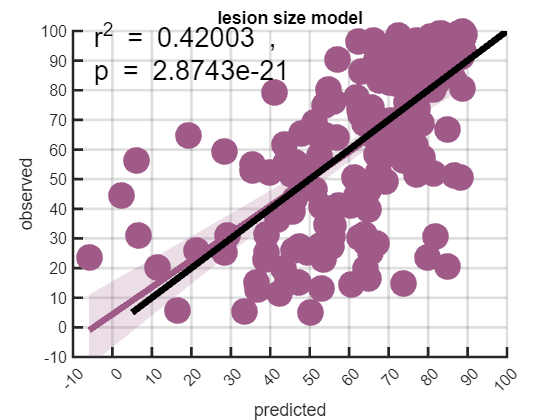

% lesion size only
sd = std(yhatLV,[],2)./sqrt(11);
m = mean(yhatLV,2);
[parts] = quickScatter(y,m,'perfectY',true','markerAlpha',1,'colorIndex',7,'err',[zeros(size(sd)) sd]);
parts.annot.Position = [0.1500    0.9000    0.3504    0.0631];set(gca,'FontSize',12);
ax = gca;
ax.XTick = [-10:10:100];
xlim([-10 100]);
parts.annot.Position = [0.1500    0.9000    0.3504    0.0631];
ax.YTick = [-10:10:100];
ylim([-10 100]);
title('lesion size model')

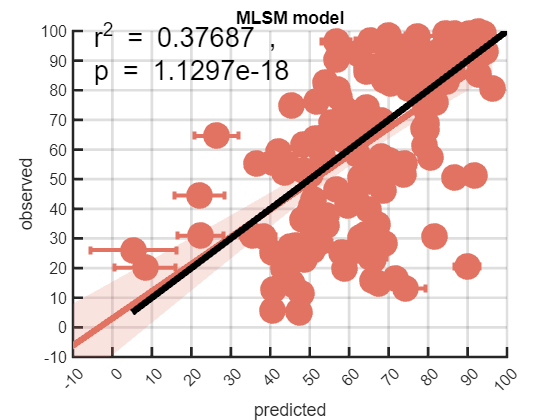

% all features
sd = std(yhatAFc,[],2)./sqrt(11);
m = mean(yhatAFc,2);
[parts] = quickScatter(y,m,'perfectY',true','markerAlpha',1,'colorIndex',5,'err',[zeros(size(sd)) sd]);
ax = gca;set(gca,'FontSize',12);
ax.XTick = [-10:10:100];
xlim([-10 100]);
parts.annot.Position = [0.1500    0.9000    0.3504    0.0631];
ax.YTick = [-10:10:100];
ylim([-10 100]);
title('MLSM model')

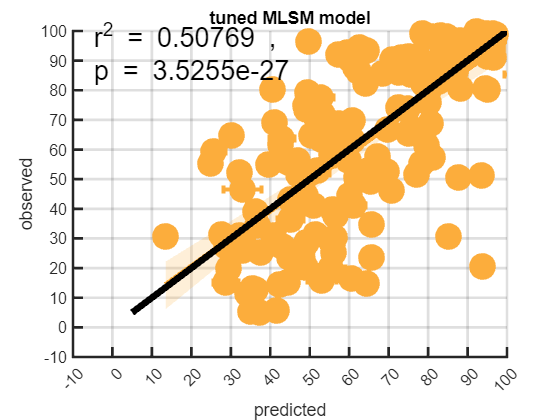

% tuned
sd = std(yhatAFT,[],2)./sqrt(11);
m = mean(yhatAFT,2);
[parts] = quickScatter(y,m,'perfectY',true','markerAlpha',1,'colorIndex',3,'err',[zeros(size(sd)) sd]);
ax = gca;set(gca,'FontSize',12);
ax.XTick = [-10:10:100];
xlim([-10 100]);
parts.annot.Position = [0.1500    0.9000    0.3504    0.0631];
ax.YTick = [-10:10:100];
ylim([-10 100]);
title('tuned MLSM model')

## Now let's see how standard deviation of feature weights changes between MLSM and sMLSM

There is one problem however--some of our models are nonlinear and the weights are not so straighforward to interpret. As a result, we will have to look at SHAP values, which are an algorithm-agnostic way of explaining a features' influence on a sample prediction based on game theory...running this will take some time--maybe an hour or so

First, let me show you the imbalance of tuned model kernels that we have...

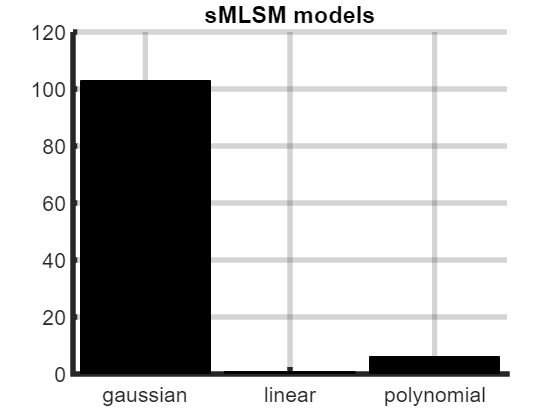

% track kernels for sMLSM
kf = [];
for i = 1:size(bmdlAF,1)
    for j = 1:size(bmdlAF,2)
            kf = [kf; {bmdlAF{i,j,nfpWinner(i,j)}.KernelParameters.Function}];
    end
end

% track kernels for MLSM
kfc = [];
for i = 1:size(bmdlAFc,1)
    for j = 1:size(bmdlAFc,2)
        kfc = [kfc; {bmdlAFc{i,j}.KernelParameters.Function}];
    end
end

% plot
figure; histogram(categorical(kf),'FaceColor',[0 0 0],'FaceAlpha',1); grid on; box off; set(gcf,'color','w');set(gca,'FontSize',16); set(gca,'LineWidth',4); set(gca,'GridAlpha',0.2); title('sMLSM models');

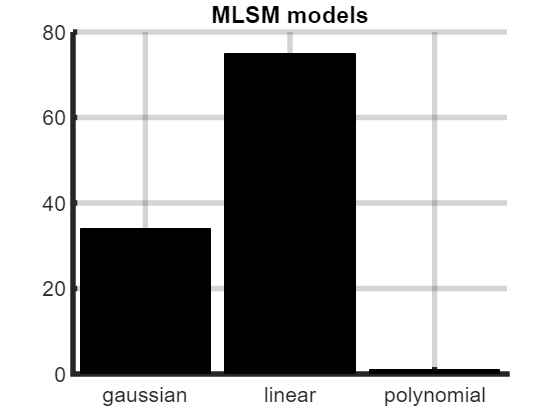

figure; histogram(categorical(kfc),'FaceColor',[0 0 0],'FaceAlpha',1); grid on; box off; set(gcf,'color','w');set(gca,'FontSize',16); set(gca,'LineWidth',4); set(gca,'GridAlpha',0.2); title('MLSM models');

As you can see, MLSM tends to favor linear kernels whereas sMLSM favors nonlinear kernels....to the point that there are almost no linear models in sMLSM! This demonstrates that starting with a smaller subset of features can permit the succesful training of more complex models, leading to better model performance.

Now we can start generating SHAP values. We use SHAP to explain each in-sample model prediction. We use the conditional kernel in order to be able to account for feature importance for nonlinear models.

% This will get SHAP for sMLSM
allweightsAF = nan(size(X,1),size(nfpWinner,1),size(X,2)+1,size(bmdlAF,2));
for i = 1:size(bmdlAF,1) % loop over training datssets in each repeat
    disp(['Working on model set ' num2str(i) ' of ' num2str(size(bmdlAF,1))])
    for r = 1:size(bmdlAF,2) % loop over repeats of cv
        explainer = shapley(bmdlAF{i,r,nfpWinner(i,r)},'Method','conditional','UseParallel',true); % generate a shap model using our training data (stored in the model object). The conditional kernel helps ensure we capture interactions
        Xtest = [X(training(c{r},i),fkfin{i}{r}{nfpWinner(i,r)}) z(training(c{r},i))]; % extract the data we want to explain using our shap model (it's the input to the model)
        id = find(training(c{r},i)); % get the indices of the training samples for next step
        for j = 1:size(Xtest,1) % looping over the training data samples that we want to explain...
            newExplainer = fit(explainer,Xtest(j,:),'Method','conditional','UseParallel',true); % fit the shap model to a sample
            tmp = newExplainer.ShapleyValues.ShapleyValue(1:end-1);
            allweightsAF(id(j),i,end,r) = NaN;
            allweightsAF(id(j),i,fkfin{i}{r}{nfpWinner(i,r)},r) = tmp;
        end
    end
end

% Now we get SHAP for our MLSM model
allweightsAFc = nan(size(X,1),size(nfpWinner,1),size(X,2)+1,size(bmdlAF,2)); % preallocate weights matrix
for r = 1:size(bmdlAFc,1)
    disp(['Working on repeat ' num2str(r) ' of ' num2str(size(bmdlAFc,1))])
    for i = 1:size(bmdlAFc,2)
        explainer = shapley(bmdlAFc{r,i},'Method','conditional','UseParallel',true); % generate a shap model using our training data (stored in the model object). The conditional kernel helps ensure we capture interactions
        Xtest = [X(training(c{r},i),:) z(training(c{r},i))];
        id = find(training(c{r},i));
        for j = 1:size(Xtest,1)
            newExplainer = fit(explainer,Xtest(j,:),'Method','conditional','UseParallel',true); % fit the shap model to a sample
            tmp = newExplainer.ShapleyValues.ShapleyValue(1:end-1);
            allweightsAFc(id(j),i,end,r) = NaN;
            allweightsAFc(id(j),i,1:end-1,r) = tmp;
        end
    end
end

Now that we have SHAP values, we can see how deviation in SHAP values differs between sMLSM and MLSM (i.e., as assessed across repeats)

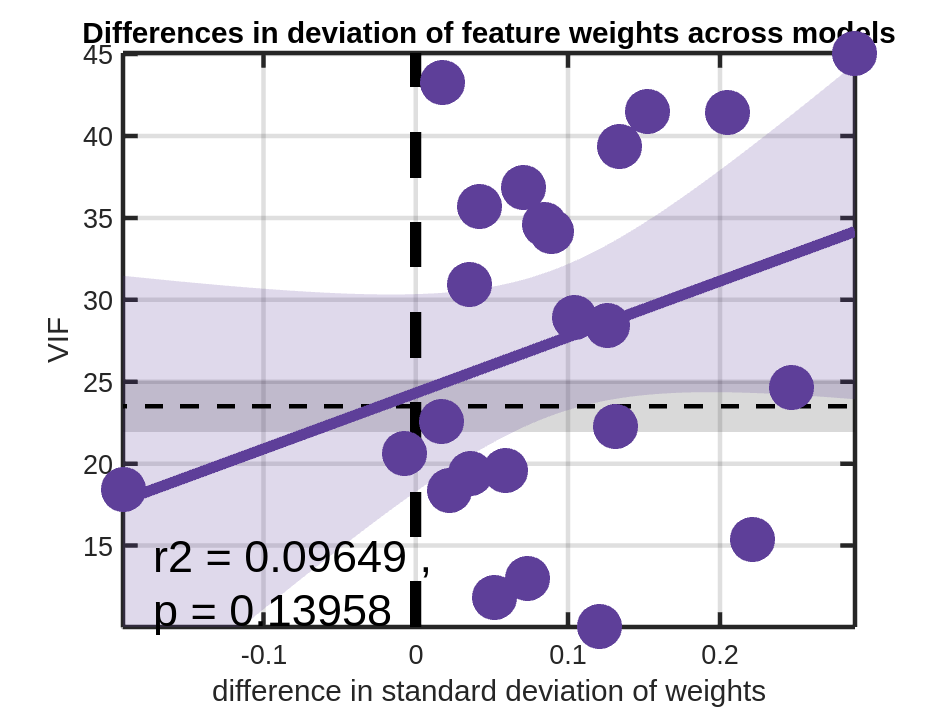

% But first, let's get a measure of each features' colinearity which may be
% interesting to relate to differences in feature importance deivation
% between models
tmp = [X z];
[num_samples, num_features] = size(tmp);
VIF = zeros(1, num_features);
for i = 1:num_features
    % Features other than the one in consideration
    other_features = [tmp(:,1:i-1) tmp(:,i+1:end)];
    
    % Regress the feature against all other features
    [~,~,~,~,stats] = regress(tmp(:,i), [ones(1,num_samples)', other_features]);
    
    % Compute VIF
    R2 = stats(1); % R-squared value
    VIF(i) = 1 / (1 - R2);
end
VIF=VIF';

% We need to collapse the data...for each feature and repeat, get median
% SHAP across training datasets first, then samples (i.e., what is the
% median feature importance for a sample in a repeat across different
% training datasets, then what is the median feature importance in a repeat
% when we collapse across all samples)
m1 = [squeeze(median(median(allweightsAF,2,'omitnan'),1,'omitnan'))];
m2 = [squeeze(median(median(allweightsAFc,2,'omitnan'),1,'omitnan'))];
m1(end,:) = []; m2(end,:) = []; % we remove lesion size temporarily for this analysis as it is an outlier with a massive VIF for the scatterplot below...

% we also want to make sure we are looking at SHAP deviation for
% "consistently" stable features because fewer values contributed to the
% point estimates of the less consistently stable features and they were
% likely an artifact of partitioning noise. We operationalize "consistent"
% as any feature that made it into a stable set in at least 80% of repeats
tmp = sum(isnan(m1), 2); % number of times a feature never appeared in a repeat
tmp = (length(c) - tmp)./length(c); % convert to proportion of repeats in which a feature appeared
id = find(tmp >= 0.8); % threshold for consistently stable features

% actual fig
s = setdiff([1:size(X,2)],id);
if ~isempty(s)
    mvif = mean(VIF(s));
    mvifsem = std(VIF(s))./sqrt(length(s));
    figure; plt1 = shadedErrorBar([-50 100],[mvif mvif],repmat([mvif-mvifsem mvif+mvifsem]',1,2));
    plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
    plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
else
    figure;
end
hold on
p2 = plot([0 0],[min(VIF(id)) max(VIF(id))],'LineWidth',3,'LineStyle','--','Color',[0 0 0]);
p2.LineWidth = 5;
[parts] = quickScatter(VIF(id),std(m2(id,:),[],2,"omitmissing")-std(m1(id,:),[],2,"omitmissing"),'perfectY',false,'useWholeMap',false,'markerAlpha',1,'newFig',false);
xlabel('difference in standard deviation of weights')
ylabel('VIF')
xlim([min(parts.scat.XData) max(parts.scat.XData)])
ylim([min(parts.scat.YData) max(parts.scat.YData)])
title('Differences in deviation of feature weights across models'); set(gca,'FontSize',12);

% now test for a difference between standard deviations of consistent
% features...the std deviations of features are normally distributed so we
% do a paired ttest here...
[~,p,~,stats] = ttest(std(m1(id,:),[],2,"omitmissing"),std(m2(id,:),[],2,"omitmissing"));
disp(['A t-test for deviation in sMLSM feature importance vs deviation in MLSM feature importance returned a pvalue of: ' num2str(p)])

A t-test for deviation in sMLSM feature importance vs deviation in MLSM feature importance returned a pvalue of: 0.00018553


disp(['The t-value indicating direction of effect was: ' num2str(stats.tstat)])

The t-value indicating direction of effect was: -4.4453


[p,~,stats] = ranksum(std(m1(id,:),[],2,"omitmissing"),std(m2(id,:),[],2,"omitmissing"));
disp(['A ranksum test for deviation in sMLSM feature importance vs deviation in MLSM feature importance returned a pvalue of: ' num2str(p)])

A ranksum test for deviation in sMLSM feature importance vs deviation in MLSM feature importance returned a pvalue of: 5.0833e-05


disp(['The z-value indicating direction of effect was: ' num2str(stats.zval)])

The z-value indicating direction of effect was: -4.0518


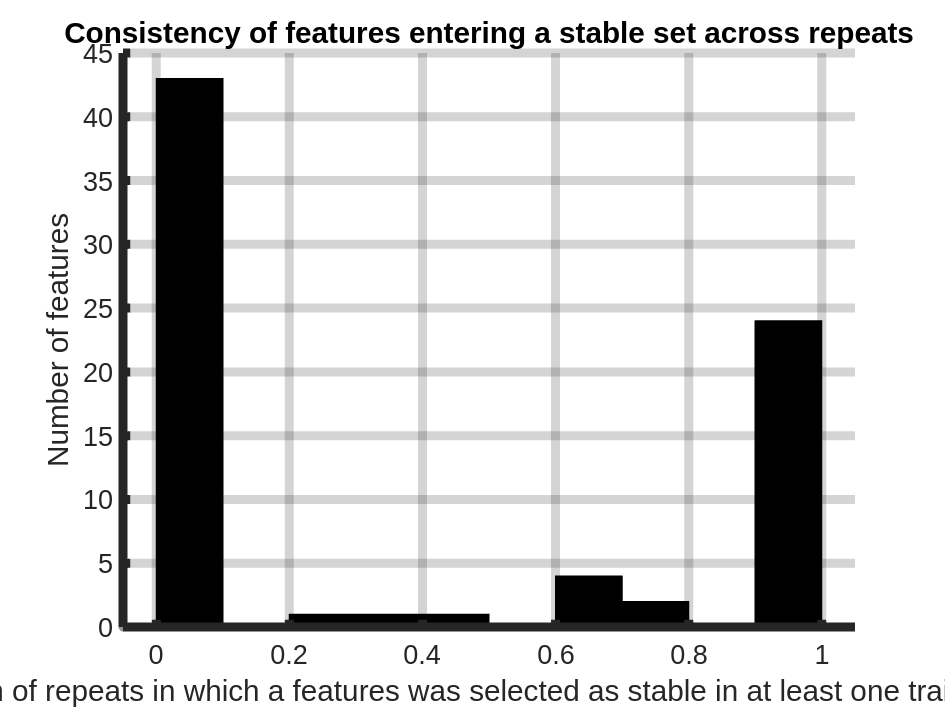

% we can also plot a histogram of feature selection consistency
figure; histogram(tmp,10,'FaceColor',[0 0 0],'FaceAlpha',1); grid on; box off; set(gcf,'color','w');set(gca,'FontSize',12); set(gca,'LineWidth',4); set(gca,'GridAlpha',0.2);
xlabel('Proportion of repeats in which a features was selected as stable in at least one training dataset')
ylabel('Number of features')
title('Consistency of features entering a stable set across repeats')

As you can see, we have many features that are never selected by stability selection in any training dataset. But we also have some features that are selected in some training datasets. 

Now we can replace NaNs with zeros. To reiterate, it makes sense not to consider 0s when we looked at standard deviation of assigned weights because if a feature was only selected in say 3 repeats, setting feature importance in the remaining repeats to 0 may "artificially" make it look like there is more consistency in sMLSM. It also makes sense to look at raw SHAP values in that context because if in some training data a feature is important for predicting low severity and in others its important for predicting high severity there is a degree of inconsistency. 

However, we also want to have a very general idea of how the patterns picked out by MLSM and sMLSM might be different. In this context, where we are collapsing across all of the data to get a gross measure of feature importance *to the model*, we want to consider consistency of feature importance in sMLSM and therefore want to include the 0s. For example, if a feature selected in 3 repeats has highly inconsistent feature weights, getting the average or median across these weights can make it look like that feature is very important due to an outlier. But if we look across all models as this analysis aims to do, we actually want to be able to notice that that feature is not very important overall and therefore want to include the 0s. Here, we also don't care whether features are assigned negative or positive weights because that assignment resulted in the most accurate model and therefore reflects the models' internal workings. Setting aside the confusing interpretation of what negative predictors might mean (i.e., a lesion indicates less aphasia severity), we just want a general idea of  how these models are treating these features differently as this is what explains their differences in performance. 

% Now replace NaNs for unselected features in sMLSM...
for i = 1:c{1}.NumTestSets % loop over training datssets in each repeat
    for r = 1:length(c) % loop over repeats of cv
        s = setdiff([1:76],fkfin{i}{r}{nfpWinner(i,r)});
        allweightsAF(training(c{r},i),i,s,r) = 0;
    end
end
m1 = [squeeze(median(median(abs(allweightsAF),2,'omitnan'),1,'omitnan'))];
m2 = [squeeze(median(median(abs(allweightsAFc),2,'omitnan'),1,'omitnan'))];

## Investigating model features and adding univariate lesion symptom mapping to our comparisons

First, let's perform simple univariate lesion symptom mapping using two-sample t-tests. We can use permutation analysis to define the p-values more robustly. The t-values from our tests will serve as a measure of feature importance for this model.

% regress lesion size out of the behavior for univariate analyses. In
% multivaraite analyses, we include lesion size in the models themselves.
mdl = fitlm(z,y,'RobustOpts','on');
yRes = mdl.Residuals.Standardized;

% we will do a permutation analysis with a 2-sample t-test
numPermutations = 10000;  % for example, 1000 permutations

% Preallocate the p-values array for permutations
permuted_p = zeros(size(X,2), numPermutations);

% Loop over each feature
for i = 1:size(X,2)
   disp(['Working on feature ' num2str(i) ' of ' num2str(size(X,2))]);

    % get lesioned and nonlesioned participants
    id1 = find(X(:,i) >= 0.1);
    id2 = find(X(:,i) < 0.1);
    
    % count number of patients in each group
    le(i,1) = length(id1);
    le(i,2) = length(id2);
    
    % Check for adequate sample sizes to test else effect is insignificant
    if le(i,1) >= 10 && le(i,2) >= 10
        % perform t-test
        [h,p(i,1),~,stats] = ttest2(yRes(id1), yRes(id2),"Tail","left");
        t(i,1) = stats.tstat;

        % Permutation test starts here
        for j = 1:numPermutations
            % Permute the response variable
            permutedLabels = yRes(randperm(length(yRes)));
            
            % Recalculate tests for the permuted data
            [~,permuted_p(i,j),~,stats] = ttest2(permutedLabels(id1), permutedLabels(id2),"Tail","left");
            permuted_t(i,j) = stats.tstat;
        end
        
        % Calculate the empirical p-values for both tests
        p_value_perm(i,1) = sum(permuted_p(i,:) <= p(i,1))./numPermutations;
        t_value_perm(i,1) = sum(permuted_t(i,:) <= t(i,1)) / numPermutations;
    else
        p(i,1) = NaN;
        t(i,1) = NaN;
        p_value_perm(i,1) = NaN; 
        t_value_perm(i,1) = NaN; 
    end
end

Working on feature 1 of 76
Working on feature 2 of 76
Working on feature 3 of 76
Working on feature 4 of 76
Working on feature 5 of 76
Working on feature 6 of 76
Working on feature 7 of 76
Working on feature 8 of 76
Working on feature 9 of 76
Working on feature 10 of 76
Working on feature 11 of 76
Working on feature 12 of 76
Working on feature 13 of 76
Working on feature 14 of 76
Working on feature 15 of 76
Working on feature 16 of 76
Working on feature 17 of 76
Working on feature 18 of 76
Working on feature 19 of 76
Working on feature 20 of 76
Working on feature 21 of 76
Working on feature 22 of 76
Working on feature 23 of 76
Working on feature 24 of 76
Working on feature 25 of 76
Working on feature 26 of 76
Working on feature 27 of 76
Working on feature 28 of 76
Working on feature 29 of 76
Working on feature 30 of 76
Working on feature 31 of 76
Working on feature 32 of 76
Working on feature 33 of 76
Working on feature 34 of 76
Working on feature 35 of 76
Working on feature 36 of 76
W

lsmpfdr = mafdr(t_value_perm,'BHFDR',true); % FDR correct p-values

Just to make sure that we are comparing apples to apples, we should perform a permutation analysis for the MLSM and sMLSM. We will perform a t-test to understand the magnitude of deviation in feature importance from zero across repeats of CV. We will then repeat this testing across permutations to see what the likelihood is of observing a statistic as extreme under the null. 

#### To start, we get true t-tests for the multivariate models...

% testing each feature vs zero to get magnitude of feature importance at
% the group-level
for i = 1:size(m1,1)
    [~,tP(i,1),~,stats] = ttest(abs(m1(i,:)),0,"Tail","right");
    tZ(i,1) = stats.tstat;
end
id = find(isnan(tZ));
tZ(id) = 0;
tP(id) = 1;
id = find(isinf(tZ));
tZ(id) = max(tZ(~isinf(tZ)));

for i = 1:size(m2,1)
    [~,tP2(i,1),~,stats] = ttest(abs(m2(i,:)),0,"Tail","right");
    tZ2(i,1) = stats.tstat;
end
id = find(isnan(tZ2));
tZ2(id) = 0;
tP2(id) = 1;
id = find(isinf(tZ2));
tZ2(id) = max(tZ2(~isinf(tZ2)));

#### Now we need to get permuted t-tests for the multivariate models...THIS WILL TAKE A VERY LONG TIME TO RUN!! In fact, we only got through a few of these so they were not included in the ms

save('JHU_sMLSM_work_in_progress.mat','-v7.3')
clearvars -except X y z fkfin nfpWinner c fkRaw m1 m2 tZ tZ2

permss = 500;
tot = 28;
for perm = 1:permss
    disp(['Working on permutation:' num2str(perm) ' of ' num2str(permss)])
    yperm = y(randperm(length(y)));
    allweightsAFcPerm = nan(size(X,1),c{1}.NumTestSets,size(X,2)+1,length(fkRaw));
    allweightsAFPerm = nan(size(X,1),c{1}.NumTestSets,size(X,2)+1,length(fkRaw));
    for r = 1:length(fkRaw) % loop over repeats of CV...
        for n = 1:tot % loop over sequence of false positives
            for i = 1:length(fkRaw{r}) % test set
                if n == 1
                    guessLVPerm(test(c{r},i),1) = mean(yperm(training(c{r},i)));
                end

                % define hyperparameters for sMLSM (same as above)
                hype = hyperparameters('fitrsvm',[X(training(c{r},i),fkfin{i}{r}{n}) z(training(c{r},i))],yperm(training(c{r},i)));
                hype(2).Optimize = false;
                hype(1).Range = [1.0000e-03 800];
                hype(4).Optimize = true;

                % Now we need to train the SVM on stable features plus lesion
                % size (sMLSM model). You can increase the number of
                % evaluations here for bayesian optimization and this
                % should improve model performance a tiny bit. Note, hype options override other arguments (e.g., KernelFunction,linear)
                bmdlAFPerm{i,n} = fitrsvm([X(training(c{r},i),fkfin{i}{r}{n}) z(training(c{r},i))],yperm(training(c{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                    'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                    'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');

                % Get sMLSM model predictions
                yhatAFPerm(test(c{r},i),1) = predict(bmdlAFPerm{i,n},[X(test(c{r},i),fkfin{i}{r}{n}) z(test(c{r},i))]);

                % now get one last control model--here we use all the
                % features
                if n == 1
                    hype = hyperparameters('fitrsvm',[X(training(c{r},i),:) z(training(c{r},i))], yperm(training(c{r},i)));
                    hype(2).Optimize = false;
                    hype(1).Range = [1.0000e-03 800];
                    hype(4).Optimize = true;

                    % Now we need to run a SVM on *all* features plus lesion size
                    bmdlAFcPerm{i} = fitrsvm([X(training(c{r},i),:) z(training(c{r},i))],yperm(training(c{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                        'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                        'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');
                    yhatAFcPerm(test(c{r},i),1) = predict(bmdlAFcPerm{i},[X(test(c{r},i),:) z(test(c{r},i))]);
                end
            end

            % compute various performance measures for each MLSM model (we
            % do this after each loop of CV so the predictions are stacked
            % across test datasets)
            if n == 1
                [AFc_corrPerm(r,perm),AFc_corrpPerm(r,perm)] = corr(yhatAFcPerm(:,1),yperm);
                AFc_maePerm(r,perm) = mean(abs(yperm-yhatAFcPerm(:,1)));
                AFc_masePerm(r,perm) = AFc_maePerm(r,perm) ./ mean(abs(y-guessLVPerm(:,1)));
                AFc_apPerm(r,perm) = (1-AFc_masePerm(r,perm))*100;
            end

            % compute various performance measures for each sMLSM model
            [AF_corrPerm(r,n,perm),AF_corrpPerm(r,n,perm)] = corr(yhatAFPerm(:,1),y);
            AF_maePerm(r,n,perm) = mean(abs(yperm-yhatAFPerm(:,1)));
            AF_masePerm(r,n,perm) = AF_maePerm(r,n,perm) ./ mean(abs(yperm-guessLVPerm(:,1)));
            AF_apPerm(r,n,perm) = (1-AF_masePerm(r,n,perm))*100;
        end

        % tune sMLSM for just THIS repeat
        clear moderr
        for i = 1:length(fkRaw{r}) % test set
            % for i, which n wins?'
            for n = 1:tot % extract model loss
                moderr(n,1) = bmdlAFPerm{i,n}.HyperparameterOptimizationResults.MinEstimatedObjective;
            end
            moderrw = moderr .* (1 + 0.002 .* [1:length(moderr)]'); % linearly weight the loss slightly to favor lower sFDR by favoring a smaller number of false positives. Note, we use this weighting across ALL analyses in our manuscript, including when testing other sample sizes and atlases
            [mv,nfpWinnerPerm] = min(moderrw);
            yhatAFTPerm(test(c{r},i),1) = predict(bmdlAFPerm{i,nfpWinnerPerm},[X(test(c{r},i),fkfin{i}{r}{nfpWinnerPerm}) z(test(c{r},i))]);
            explainer = shapley(bmdlAFPerm{i,nfpWinnerPerm},'Method','conditional','UseParallel',true);
            Xtest = [X(training(c{r},i),fkfin{i}{r}{nfpWinnerPerm}) z(training(c{r},i))]; % extract the data we want to explain using our shap model (it's the input to the model)
            id = find(training(c{r},i)); % get the indices of the training samples for next step
            for j = 1:size(Xtest,1) % looping over the training data samples that we want to explain...
                newExplainer = fit(explainer,Xtest(j,:),'Method','conditional','UseParallel',true); % fit the shap model to a sample
                tmp = newExplainer.ShapleyValues.ShapleyValue(1:end-1);
                allweightsAFPerm(id(j),i,end,r) = newExplainer.ShapleyValues.ShapleyValue(end);
                allweightsAFPerm(id(j),i,fkfin{i}{r}{nfpWinnerPerm},r) = tmp;
            end
        end
        [AF_corrTPerm(r,perm),AF_corrpTPerm(r,perm)] = corr(yhatAFTPerm(:,1),yperm);
        AF_maeTPerm(r,perm) = mean(abs(yperm-yhatAFTPerm(:,1)));
        AF_maseTPerm(r,perm) = AF_maeTPerm(r,perm) ./ mean(abs(yperm-guessLVPerm(:,1)));
        AF_apTPerm(r,perm) = (1-AF_maseTPerm(r,perm))*100;

        % get shap for MLSM
        for i = 1:length(bmdlAFcPerm)
            explainer = shapley(bmdlAFcPerm{i},'Method','conditional','UseParallel',true); % generate a shap model using our training data (stored in the model object). The conditional kernel helps ensure we capture interactions
            Xtest = [X(training(c{r},i),:) z(training(c{r},i))];
            id = find(training(c{r},i));
            for j = 1:size(Xtest,1)
                newExplainer = fit(explainer,Xtest(j,:),'Method','conditional','UseParallel',true); % fit the shap model to a sample
                tmp = newExplainer.ShapleyValues.ShapleyValue(1:end-1);
                allweightsAFcPerm(id(j),i,end,r) = newExplainer.ShapleyValues.ShapleyValue(end);
                allweightsAFcPerm(id(j),i,1:end-1,r) = tmp;
            end
        end
    end

    % collapse across all training datasets
    m1Perm(:,:,perm) = squeeze(median(median(abs(allweightsAFPerm),2,'omitnan'),1,'omitnan'));
    m2Perm(:,:,perm) = squeeze(median(median(abs(allweightsAFcPerm),2,'omitnan'),1,'omitnan'));

    % test vs zero across repeats
    for i = 1:size(m1Perm,1)
        try
            [~,tPPerm(i,perm),~,stats] = ttest(abs(m1Perm(i,:,perm)),0,"Tail","right");
            tZPerm(i,perm) = stats.tstat;
        catch
            tPPerm(i,perm) = NaN;
            tZPerm(i,perm) = NaN;
        end
    end
    id = find(isnan(tZPerm(:,perm)));
    tZPerm(id,perm) = 0;
    tPPerm(id,perm) = 1;
    id = find(isinf(tZPerm(:,perm)));
    tZPerm(id,perm) = max(tZPerm(~isinf(tZPerm(:,perm)),perm));

    for i = 1:size(m2Perm,1)
        try
            [~,tP2Perm(i,perm),~,stats] = ttest(abs(m2Perm(i,:,perm)),0,"Tail","right");
            tZ2Perm(i,perm) = stats.tstat;
        catch
            tP2Perm(i,perm) = NaN;
            tZ2Perm(i,perm) = NaN;
        end
    end
    id = find(isnan(tZ2Perm(:,perm)));
    tZ2Perm(id,perm) = 0;
    tP2Perm(id,perm) = 1;
    id = find(isinf(tZ2Perm(:,perm)));
    tZ2Perm(id,perm) = max(tZ2Perm(~isinf(tZ2Perm(:,perm))));
    try
        save('JHU_perms_stab.mat');
    catch
        save('JHU_perms_stab.mat','-v7.3');

Unrecognized function or variable 'tZPerm'.

    end
end

## Plot unthresholded LSM, MLSM and sMLSM maps

Now we need to plot the unthresholded maps. This code shows you how to use brainSurfer outside of the GUI but if you want to make prettier figures, please use the GUI!!

% you may want to clear the permutation variables before proceeding!
bd = which('brainSurfer.mlapp');
[bd, ~, ~] = fileparts(bd);
[vert1,face1] = read_surf(fullfile(bd,'brains','lh.inflated'));
[underlay, brainFig, ~, ~] = patchUnderlay(vert1, face1);

ans = 0

sg = read_curv(fullfile(bd,'brains','lh.curv'));
[underlay, ~, ~] = patchUnderlaySG(underlay, 'lh', sg,'invertColors','on','limits',[0 1],'binarize',0);
hold on;
rids = str2double(extractBefore(cellstr(labs),'|'));
lh = load_nifti(fullfile(bd,'atlases','jhu_resampled_to_FSL_fixed_noWM_CombinedClusters_FSSpace_LH.nii.gz'));

ol = zeros(size(lh.vol));
for i = 1:length(rids)
    vid = find(lh.vol == rids(i));
    ol(vid) = tZ(i);
end
patchOverlay(brainFig,ol,underlay,'left','colormap','viridis','limits',[0 80],'opacity',0.8);

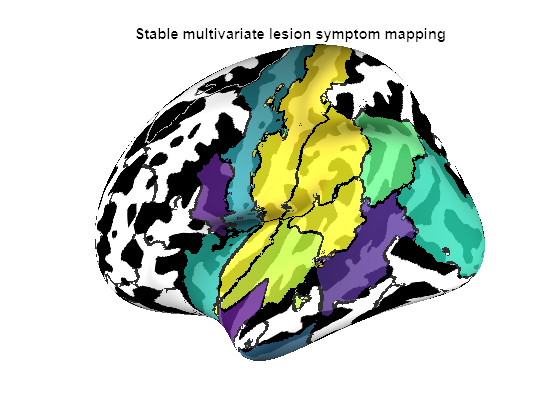

patchOverlay(brainFig,lh.vol,underlay,'left','colormap','gray','limits',[1 2],'opacity',0.8,'outline','roi','invertColors','on','colorBins',2);
title('Stable multivariate lesion symptom mapping')

lh.vol = ol;
save_nifti(lh,'sMLSM_unthresholded_LH.nii.gz'); % you can startup the brainSurfer GUI and load this in to make fancier plots
lh = load_nifti(fullfile(bd,'atlases','jhu_resampled_to_FSL_fixed_noWM_CombinedClusters_FSSpace_LH.nii.gz'));

ol = zeros(size(lh.vol));
for i = 1:length(rids)
    vid = find(lh.vol == rids(i));
    ol(vid) = tZ2(i);
end
[underlay, brainFig, ~, ~] = patchUnderlay(vert1, face1);

ans = 0

sg = read_curv(fullfile(bd,'brains','lh.curv'));
[underlay, ~, ~] = patchUnderlaySG(underlay, 'lh', sg,'invertColors','on','limits',[0 1],'binarize',0);
hold on;
patchOverlay(brainFig,ol,underlay,'left','colormap','viridis','limits',[0 80],'opacity',0.9);

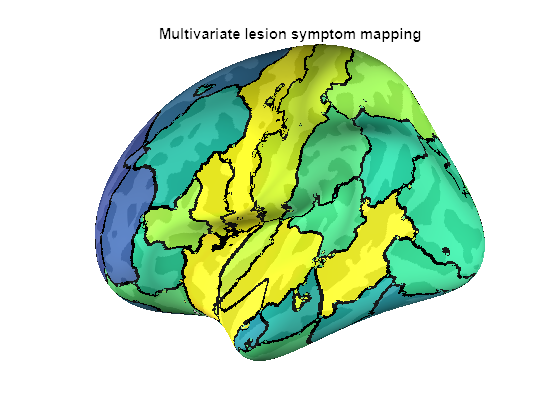

patchOverlay(brainFig,lh.vol,underlay,'left','colormap','gray','limits',[1 2],'opacity',0.9,'outline','roi','invertColors','on','colorBins',1);
title('Multivariate lesion symptom mapping')

lh.vol = ol;
save_nifti(lh,'MLSM_unthresholded_LH.nii.gz'); % you can startup the brainSurfer GUI and load this in to make fancier plots

lh = load_nifti(fullfile(bd,'atlases','jhu_resampled_to_FSL_fixed_noWM_CombinedClusters_FSSpace_LH.nii.gz'));

ol = zeros(size(lh.vol));
for i = 1:length(rids)
    vid = find(lh.vol == rids(i));
    ol(vid) = -1*t(i); % in severity low is high so we want lesioned vs nonlesioned to show a low t-value, indicated more severity
end
[underlay, brainFig, ~, ~] = patchUnderlay(vert1, face1);

ans = 0

sg = read_curv(fullfile(bd,'brains','lh.curv'));
[underlay, ~, ~] = patchUnderlaySG(underlay, 'lh', sg,'invertColors','on','limits',[0 1],'binarize',0);
hold on;
patchOverlay(brainFig,ol,underlay,'left','colormap','viridis','limits',[0 2],'opacity',0.8);

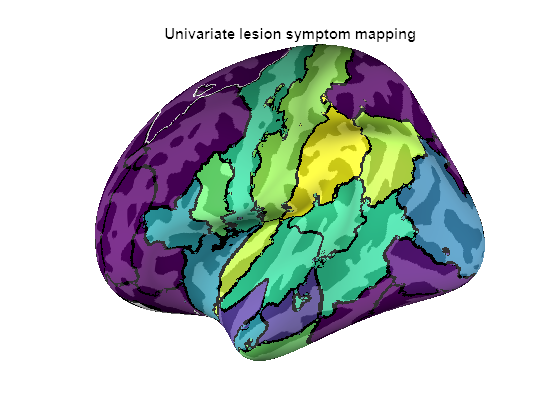

patchOverlay(brainFig,lh.vol,underlay,'left','colormap','gray','limits',[1 2],'opacity',0.8,'outline','roi','invertColors','on','colorBins',2);
title('Univariate lesion symptom mapping')

lh.vol = ol;
save_nifti(lh,'LSM_unthresholded_LH.nii.gz'); % you can startup the brainSurfer GUI and load this in to make fancier plots

Here we will generate the univariate analysis figure but using the results of our permutation analysis to evaluate significance.

pid = find(t_value_perm < 0.05);
labs(pid,:)

ans = 10×117 char array
    '23|PoCG_L|postcentral gyrus left|1                                                                                   '
    '29|SMG_L|supramarginal gyrus left|1                                                                                  '
    '31|AG_L|angular gyrus left|1                                                                                         '
    '45|PHG_L|parahippocampal gyrus left|1                                                                                '
    '119|SCR_L|superior corona radiata left|2                                                                             '
    '135|RLIC_L|retrolenticular part of internal capsule left|2                                                           '
    '137|EC_L|external capsule left|2                                                                                     '
    '143|Fx/ST_L|fornix (cres) / Stria terminalis (can not be resolved with current resolution) left|2      

lh = load_nifti(fullfile(bd,'atlases','jhu_resampled_to_FSL_fixed_noWM_CombinedClusters_FSSpace_LH.nii.gz'));
ol = zeros(size(lh.vol));
for i = 1:length(pid)
    vid = find(lh.vol == rids(pid(i)));
    ol(vid) = -1*t(pid(i));
end
[underlay, brainFig, ~, ~] = patchUnderlay(vert1, face1);

ans = 0

sg = read_curv(fullfile(bd,'brains','lh.curv'));
[underlay, ~, ~] = patchUnderlaySG(underlay, 'lh', sg,'invertColors','on','limits',[0 1],'binarize',0);
hold on;
patchOverlay(brainFig,ol,underlay,'left','colormap','viridis','limits',[0 2],'opacity',0.8);

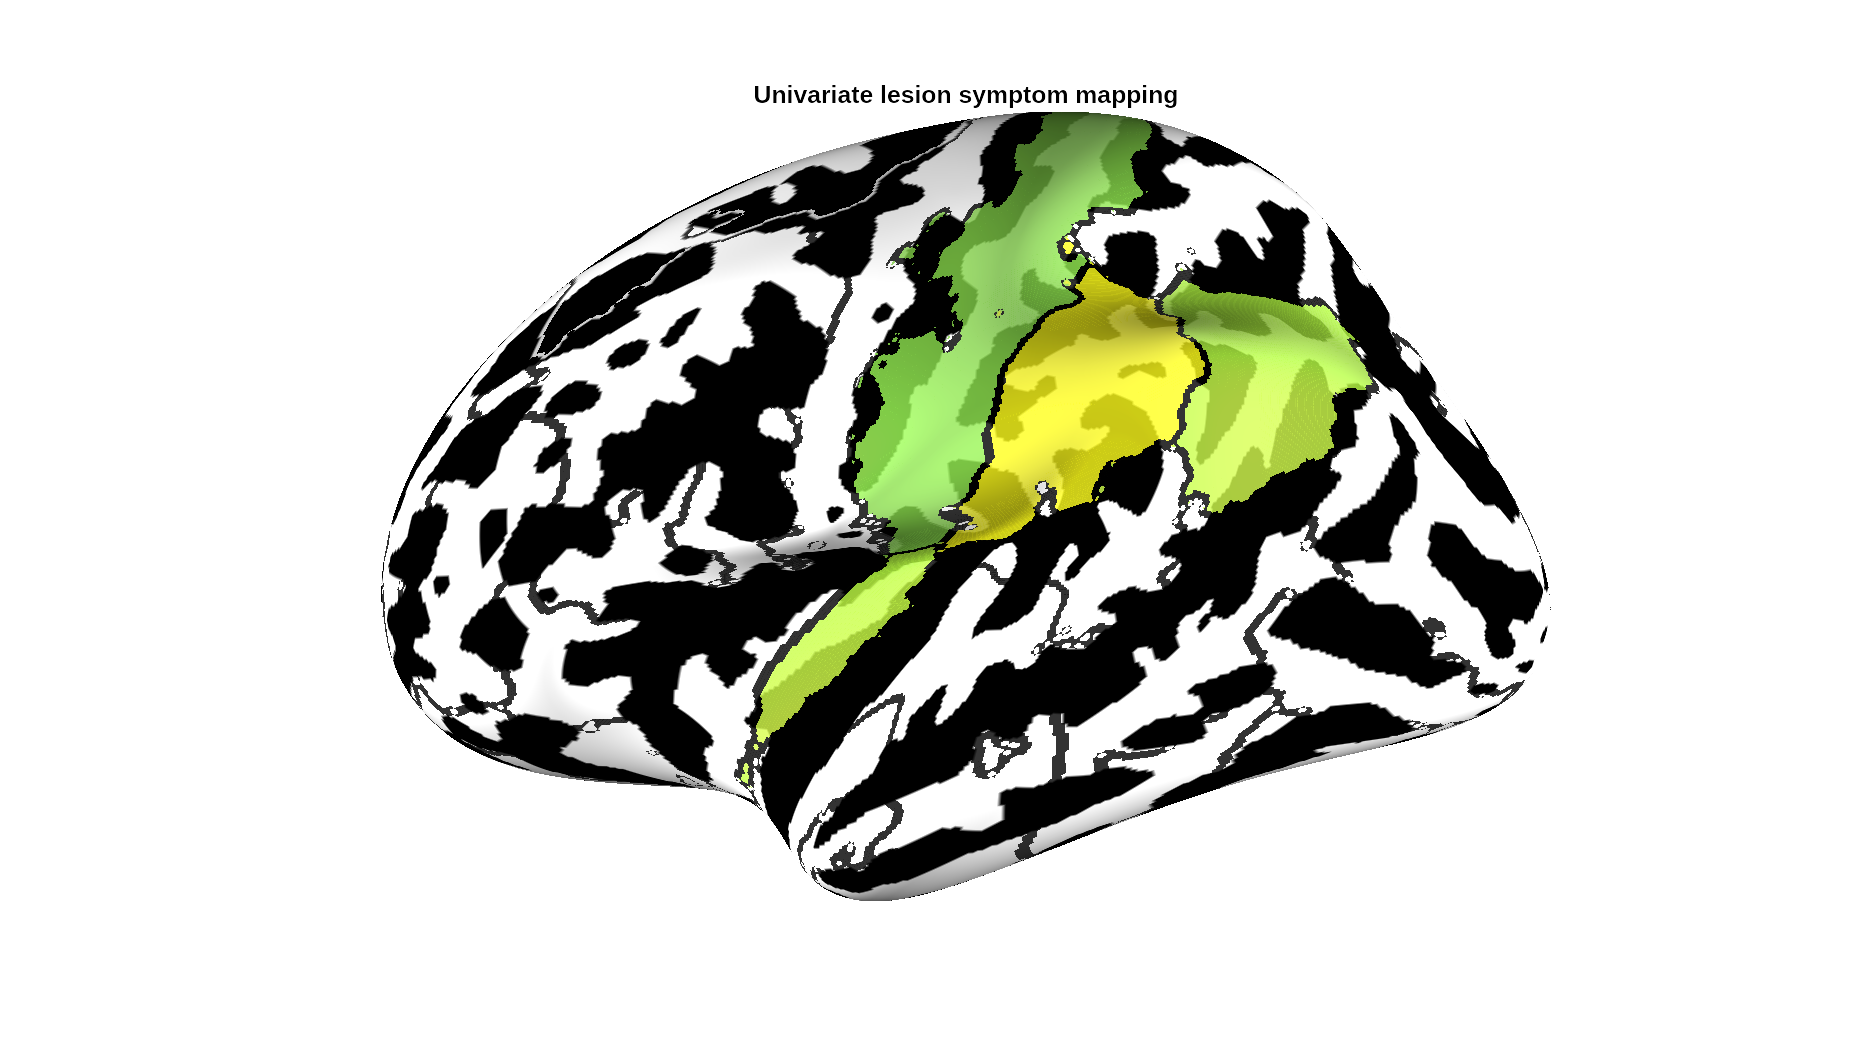

patchOverlay(brainFig,lh.vol,underlay,'left','colormap','gray','limits',[1 2],'opacity',0.8,'outline','roi','invertColors','on','colorBins',2);
title('Univariate lesion symptom mapping')

lh.vol = ol;
save_nifti(lh,'LSM_thresholded_LH.nii.gz'); % you can startup the brainSurfer GUI and load this in to make fancier plots

## Finally, test significance of stability selection--what happens if we select the same number of features randomly?

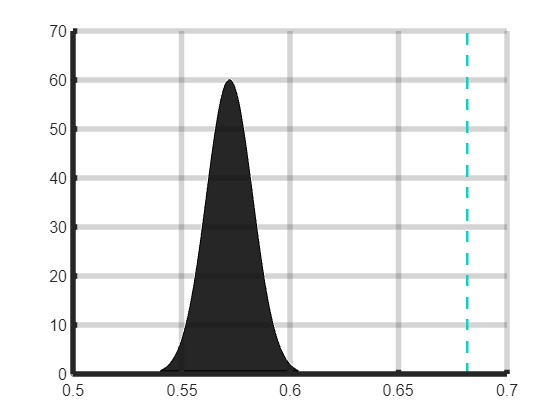

% first, let's save our workspace so that we can load it in later, we will
% really need all the memory we can get for this analysis
save('JHU_sMLSM_work_in_progress.mat','-v7.3')
clearvars -except X y z fkfin nfpWinner c
permss = 500;
for perm = 1:permss
    disp(['Working on permutation:' num2str(perm) ' of ' num2str(permss)])
    for r = 1:length(c) % loop over repeats of CV...
        for i = 1:c{r}.NumTestSets % test set
            guessLVPerms(test(c{r},i),1) = mean(y(training(c{r},i)));
            tmp = randperm(size(X,2));
            fkPerm = tmp(1:length(fkfin{i}{r}{nfpWinner(i,r)}));

            % define hyperparameters for sMLSM (same as above)
            hype = hyperparameters('fitrsvm',[X(training(c{r},i),fkPerm) z(training(c{r},i))],y(training(c{r},i)));
            hype(2).Optimize = false;
            hype(1).Range = [1.0000e-03 800];
            hype(4).Optimize = true;

            % Now we need to train the SVM on stable features plus lesion
            % size (sMLSM model). You can increase the number of
            % evaluations here for bayesian optimization and this
            % should improve model performance a tiny bit. Note, hype options override other arguments (e.g., KernelFunction,linear)
            bmdlAFPerms{i} = fitrsvm([X(training(c{r},i),fkPerm) z(training(c{r},i))],y(training(c{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');

            % Get sMLSM model predictions
            yhatAFPerms(test(c{r},i),1) = predict(bmdlAFPerms{i},[X(test(c{r},i),fkPerm) z(test(c{r},i))]);
        end
        % compute various performance measures for each sMLSM model
        [AF_corrPerms(r,perm),AF_corrpPerms(r,perm)] = corr(yhatAFPerms(:,1),y);
        AF_maePerms(r,perm) = mean(abs(y-yhatAFPerms(:,1)));
        AF_masePerms(r,perm) = AF_maePerms(r,perm) ./ mean(abs(y-guessLVPerms(:,1)));
        AF_apPerms(r,perm) = (1-AF_masePerms(r,perm))*100;
    end
end
save('JHU_perms_stab.mat','-v7.3');

% compare perms here
load('JHU_sMLSM_work_in_progress','AF_corrT_sem','AF_corrT_m','AF_apT_sem','AF_apT_m')
figure; h = histfit(mean(AF_corrPerms,1)); 
hold on;
patch(h(2).XData,h(2).YData,'k','FaceColor','k','FaceAlpha',0.85);
set(gcf,'color','w');set(gca,'FontSize',12); set(gca,'LineWidth',4); box off; grid on; set(gca,'GridAlpha',0.2);
xlim([0.5 0.7])
h(1).FaceAlpha = 0 ;
h(1).EdgeAlpha = 0 ;
hold on;
plt3 = shadedErrorBar([AF_corrT_m AF_corrT_m],[0 70],repmat([AF_corrT_m-AF_corrT_sem AF_corrT_m+AF_corrT_sem]',1,2));
plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
plt3.patch.FaceColor = plt3.mainLine.Color;

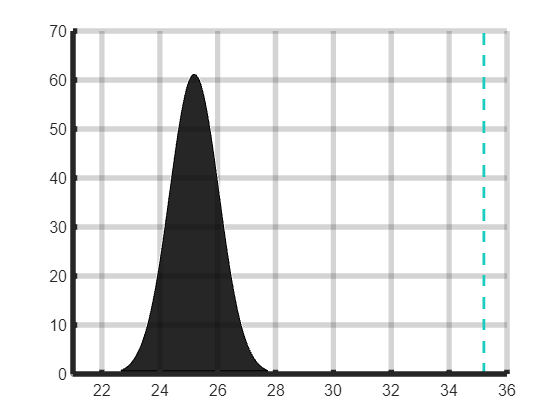

h(2).Color = [1 1 1];
figure; h = histfit(mean(AF_apPerms,1)); 
hold on;
patch(h(2).XData,h(2).YData,'k','FaceColor','k','FaceAlpha',0.85);
set(gcf,'color','w');set(gca,'FontSize',12); set(gca,'LineWidth',4); box off; grid on; set(gca,'GridAlpha',0.2);
xlim([21 36])
h(1).FaceAlpha = 0 ;
h(1).EdgeAlpha = 0 ;
hold on;
plt3 = shadedErrorBar([AF_apT_m AF_apT_m],[0 70],repmat([AF_apT_m-AF_apT_sem AF_apT_m+AF_apT_sem]',1,2));
plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
plt3.patch.FaceColor = plt3.mainLine.Color;

h(2).Color = [1 1 1];

# Analysis 2: Varying the sample size over dozens of repeats of cross validation

#### A brief note: the below analyses simply combine elements of code introduced above and figures for them can be easily adapted from the code for analysis 1 but are not automatically generated for you at the moment. We will add more documentation to this code and add automatic figure generation in the next update. 

WARNING: This will take a substantial amount of time to run (on the order of days even for a modern desktop with a top of the line CPU).

clearvars -except X y z
X = X'; % we transpose the matrix for the code below but you could easily rewrite this

% load lesion size for stratified partitioning
load('JHU_lesion_categories.mat','cat')

% get random subsamples and rerun stabSel on them
smpsz = [35:20:155 167]; % define our sample sizes to test
for r = 1:50
    for s = 1:length(smpsz)
        smpc{s,r} = cvpartition(cat,"Holdout",smpsz(s)./size(X,2),'Stratify',true);
        X2 = X(:,test(smpc{s,r},1))';
        y2 = y(test(smpc{s,r},1))';
        c2{s,r} = cvpartition(size(X2,1),"KFold",10);
        for i = 1:c2{s,r}.NumTestSets
            disp(num2str(i))
            % we reduced the number of repeats in stability selection for
            % tractability
            [fkRaw{r}{s}{i},~,probRaw{r}{s}{i},~,~,~,~,~,~,~,~,empMaxVarsRaw{r}{s}{i},~,~,~] = stabSel(X2(training(c2{s,r},i),:),y2(training(c2{s,r},i))','selAlgo','en',...
                'samType','subsample','rep',300,'compPars',false,'numFalsePos',3,'maxVars',size(X2,2)./2,'keepScores',false,...
                'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.1:1],'fixMax',true,'prop',0.5,'verbose',true);
        end
        save('smpSz_analysis.mat')
    end                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       
end

tot = 20; % we reduced this too to reduce compute as our previous analysis shows NFP of <=8 was always selected but we want to give enough room here for things to change as a function of sample size (e.g., maybe stability selection tuning breaks down)
ym = mean(y);
for r = 1:60 % number of repeats of CV for each sample size
    disp(num2str(r))
    for s = 1:length(smpsz)
        X2 = X(:,test(smpc{s,r},1))';
        y2 = y(test(smpc{s,r},1))';
        z2 = z(test(smpc{s,r},1))';
        for n = 1:tot
            for i = 1:10 % test set
                % first define your features...
                fkfin{i}{r}{s}{n} = recompStableFeats(probRaw{r}{s}{i},empMaxVarsRaw{r}{s}{i},n);

                id = find(fkfin{i}{r}{s}{n} > size(X2,2));
                fkfin{i}{r}{s}{n}(id) = [];

                if isempty(fkfin{i}{r}{s}{n})
                    fkfin{i}{r}{s}{n} = [1:size(X2,2)];
                end

                % also get training dataset-based naive predictions
                guessLV{r}(test(c2{s,r},i),1) = mean(y2(training(c2{s,r},i)));

                hype = hyperparameters('fitrsvm',[X2(training(c2{s,r},i),fkfin{i}{r}{s}{n}) z2(training(c2{s,r} ,i))'],y2(training(c2{s,r},i)));
                hype(2).Optimize = false;
                hype(1).Range = [1.0000e-03 800];
                hype(4).Optimize = true;

                % Now we need to run a SVM on *all* features plus lesion size
                bmdlAF = fitrsvm([X2(training(c2{s,r},i),fkfin{i}{r}{s}{n}) z2(training(c2{s,r} ,i))'],y2(training(c2{s,r} ,i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                    'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName','expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');

                errTrack(r,s,n,i) = bmdlAF.HyperparameterOptimizationResults.MinEstimatedObjective;
                yhatAF{r}{s}{n}(test(c2{s,r},i),1) = predict(bmdlAF,[X2(test(c2{s,r},i),fkfin{i}{r}{s}{n}) z2(test(c2{s,r} ,i))']);
            end
            [AF_corr(r,s,n),AF_corrp(r,s,n)] = corr(yhatAF{r}{s}{n}(:,1),y2');
            AF_mae(r,s,n) = mean(abs(y2'-yhatAF{r}{s}{n}(:,1)));
            AF_mase(r,s,n) = AF_mae(r,s,n) ./ mean(abs(y2-guessLV{r}(:,1)'));
            AF_ap(r,s,n) = (1-AF_mase(r,s,n))*100;
        end
        save('smpsz_analysis_models.mat','-v7.3') % 2 includes error for tuning...
    end
end

% let's not forget to run baseline models with varying sample sizes...
clear guessLV
for r = 1:60
    disp(num2str(r))
    for s = 1:length(smpsz)
        X2 = X(:,test(smpc{s,r},1))';
        y2 = y(test(smpc{s,r},1))';
        z2 = z(test(smpc{s,r},1))';
        for i = 1:10 % test set
           
            % also get training dataset-based naive predictions
            guessLV{r}{s}(test(c2{s,r},i),1) = mean(y2(training(c2{s,r},i)));

            hype = hyperparameters('fitrsvm',z2(training(c2{s,r} ,i))',y2(training(c2{s,r},i)));
            hype(2).Optimize = false;
            hype(1).Range = [1.0000e-03 800];
            hype(4).Optimize = true;

            % Now we need to run a SVM on *all* features plus lesion size
            bmdlAF = fitrsvm(z2(training(c2{s,r} ,i))',y2(training(c2{s,r} ,i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName','expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');

            yhatAFL{r}{s}(test(c2{s,r},i),1) = predict(bmdlAF,z2(test(c2{s,r} ,i))');
        end
        [AF_corrL(r,s),AF_corrpL(r,s)] = corr(yhatAFL{r}{s}(:,1),y2');
        AF_maeL(r,s) = mean(abs(y2'-yhatAFL{r}{s}(:,1)));
        AF_maseL(r,s) = AF_maeL(r,s) ./ mean(abs(y2-guessLV{r}{s}(:,1)'));
        AF_apL(r,s) = (1-AF_maseL(r,s))*100;
        save('smpsz_analysis_control.mat')
    end
end

% and now an all feature model...
for r = 1:60
    disp(num2str(r))
    for s = 1:length(smpsz)
        X2 = X(:,test(smpc{s,r},1))';
        y2 = y(test(smpc{s,r},1))';
        z2 = z(test(smpc{s,r},1))';
        for i = 1:10 % test set
           
            hype = hyperparameters('fitrsvm',[X2(training(c2{s,r},i),:) z2(training(c2{s,r} ,i))'],y2(training(c2{s,r},i)));
            hype(2).Optimize = false;
            hype(1).Range = [1.0000e-03 800];
            hype(4).Optimize = true;

            % Now we need to run a SVM on *all* features plus lesion size
            bmdlAF = fitrsvm([X2(training(c2{s,r},i),:) z2(training(c2{s,r} ,i))'],y2(training(c2{s,r} ,i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName','expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');

            yhatAFA{r}{s}(test(c2{s,r},i),1) = predict(bmdlAF,z2(test(c2{s,r} ,i))');
        end
        [AF_corrA(r,s),AF_corrpA(r,s)] = corr(yhatAFA{r}{s}(:,1),y2');
        AF_maeA(r,s) = mean(abs(y2'-yhatAFA{r}{s}(:,1)));
        AF_maseA(r,s) = AF_maeA(r,s) ./ mean(abs(y2-guessLV{r}{s}(:,1)'));
        AF_apA(r,s) = (1-AF_maseA(r,s))*100;
        save('smpsz_analysis_control.mat') %
    end
end

# Analysis 3: Testing atlas resolution

In this analysis we will use the multiresolution atlas we visualized in the beginning of the tutorial. All we do here is combine elements of the code from analysis 1 and loop over resolutions of the atlas. 

clear all
load('prepARC2.mat')
X = X([1 3 5 7 9]); % we are going to restrict which "resuolutions" we look at for the sake of time -- notice, X is transposed here with features as rows (inside the resolution cell array)

% setting up cross-validation schemes
q = quantile(z,[0.25 0.5 0.75]); 
cat = zeros(1,length(z));
cat(z <= q(1)) = 1; %1st lesion size category (<= 1st quartile)
cat(z > q(1) & z <= q(2)) = 2; % 2nd lesion size category (> 1st quartile and <= median)
cat(z > q(2) & z <= q(3)) = 3; % 3rd lesion size category (> median and <= 3rd quartile)
cat(z > q(3)) = 4; % 4th lesion size category (> 3rd quartile)
for j = 1:20
    c2{j} = cvpartition(cat,"KFold",10,"Stratify",true);
end

% running stability selection
for r = 1:length(c2)
    for j = 1:length(X)
        for i = 1:c2{r}.NumTestSets
            disp(['Working on outer fold:' num2str(i)])
            [fkRaw{j}{i}{r},~,probRaw{j}{i}{r},~,~,~,~,~,~,~,~,empMaxVarsRaw{j}{i}{r},~,~,~] = stabSel([X{j}(:,training(c2{r},i))' z(training(c2{r},i))],y(training(c2{r},i)),'selAlgo','en',...
                'samType','subsample','rep',500,'compPars',false,'numFalsePos',3,'maxVars',size(X{j},1)./2,'keepScores',false,...
                'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.05:1],'fixMax',true,'prop',0.5,'verbose',true);
        end
    end
end
save('Multires_stabSel_results.mat','-v7.3')

tot = 30;
for a = 1:length(fkRaw) % atlas index
    disp(num2str(a))
    for r = 1:length(fkRaw{a}{1}) % repeat
        for n = 1:tot
            for i = 1:length(fkRaw{a}) % test set
                % first define your features...
                t = ((((empMaxVarsRaw{a}{i}{r}.^2)/size(X{a},1))/n)+1)/2;
                fkfin{a}{i}{r}{n} = find(probRaw{a}{i}{r} > t);

                if a == 1 % we only need to do this for the first atlas as y and z are identical for all atlases
                    hype = hyperparameters('fitrsvm',z(training(c2{r},i)),y(training(c2{r},i)));
                    hype(2).Optimize = false;
                    hype(1).Range = [1.0000e-03 800]; 
                    hype(4).Optimize = true;

                    % you can choose whether to do a simple linear
                    % regression here or a SVM
                    %bmdlLV{i} = fitlm(z(training(c2{r},i)),y(training(c2{r},i)),'RobustOpts','on');
                    bmdlLV{i} = fitrsvm([X{a}(fkfin{a}{i}{r}{n},training(c2{r},i))' z(training(c2{r},i))],y(training(c2{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                        'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                        'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');

                    % use lesion size model to get test set residuals (for some
                    % models we will predict these)
                    yhatLV(test(c2{r},i),r) = predict(bmdlLV{i},z(test(c2{r},i)));

                    % also get training dataset-based naive predictions
                    guessLV(test(c2{r},i),r) = mean(y(training(c2{r},i)));
                end

                hype = hyperparameters('fitrsvm',[X{a}(fkfin{a}{i}{r}{n},training(c2{r},i))' z(training(c2{r},i))],y(training(c2{r},i)));
                hype(2).Optimize = false;
                hype(1).Range = [1.0000e-03 800];
                hype(4).Optimize = true;

                % Now we need to run a SVM on *all* features plus lesion size
                bmdlAF{a,i,r,n} = fitrsvm([X{a}(fkfin{a}{i}{r}{n},training(c2{r},i))' z(training(c2{r},i))],y(training(c2{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                    'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                    'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');
                yhatAF(test(c2{r},i),a,r,n) = predict(bmdlAF{a,i,r,n},[X{a}(fkfin{a}{i}{r}{n},test(c2{r},i))' z(test(c2{r},i))]);
            end
            [AF_corr(a,r,n),AF_corrp(a,r,n)] = corr(yhatAF(:,a,r,n),y);
            AF_mae(a,r,n) = mean(abs(y-yhatAF(:,a,r,n)));
            AF_mase(a,r,n) = AF_mae(a,r,n) ./ mean(abs(y-guessLV(:,r)));
            AF_ap(a,r,n) = (1-AF_mase(a,r,n))*100;
        end

        % plot some results as you go...
        close all
        tmp = squeeze(mean(AF_corr,2));
        figure; plot(tmp');title('correlation')
        hold on;
        plot([1:tot],repmat(tmp(1),1,tot),'Color','k','LineStyle','--');
                
        tmp = squeeze(mean(AF_ap,2));
        figure; plot(tmp');title('AP')
        hold on;
        plot([1:tot],repmat(tmp(1),1,tot),'Color','k','LineStyle','--');
    end
end

% get tuned models...
tot = 30;
for a = 1:length(X)
    for r = 1:length(c2)
        disp(num2str(r))
        for i = 1:c2{1}.NumTestSets % test set
            % for i, which n wins?'
            for n = 1:tot
                if nfk_m(n,a) ~= 0
                    moderr(n,1) = bmdlAF{a,i,r,n}.HyperparameterOptimizationResults.MinEstimatedObjective;
                else
                    moderr(n,1) = NaN;
                end
            end
            moderrw = moderr .* (1 + 0.002 .* [1:length(moderr)]'); 
            [mv,nfpWinner(a,i,r)] = min(moderrw);
            yhatAFT(test(c2{r},i),r,a) = predict(bmdlAF{a,i,r,nfpWinner(a,i,r)},[X{a}(fkfin{a}{i}{r}{nfpWinner(a,i,r)},test(c2{r},i))' z(test(c2{r},i))]);
        end
        [AF_corrT(a,r,1),AF_corrpT(a,r,1)] = corr(yhatAFT(:,r,a),y);
        AF_maeT(a,r,1) = mean(abs(y-yhatAFT(:,r,a)));
        AF_maseT(a,r,1) = AF_maeT(a,r,1) ./ mean(abs(y-guessLV(:,r)));
        AF_apT(a,r,1) = (1-AF_maseT(a,r,1))*100;
    end

    AF_corrT_m(a,1) = mean(AF_corrT(a,:))
    AF_apT_m(a,1) = mean(AF_apT(a,:))

    AF_corrT_sem(a,1) = std(AF_corrT(a,:))./length(AF_corrT(a,:));
    AF_apT_sem(a,1) = std(AF_apT(a,:))./length(AF_corrT(a,:));
end
save('Multires_sMLSM_results.mat','-v7.3')

% we need to come up with pfer instead of nfp...
for a = 1:length(X)
    for i = 1:c2{1}.NumTestSets
        for r = 1:length(c2)
            for n = 1:30
                nfp(a,i,r,n) = length(fkfin{a}{i}{r}{n});
                pfer(a,i,r,n) = n./nfp(a,i,r,n);
            end
        end
    end
end

for a = 1:length(X)
    nfk_m(:,a) = mean(squeeze(mean((squeeze(nfp(a,:,:,:))),1,'omitnan')),1,'omitnan');
    pfer_m(:,a) = mean(squeeze(mean((squeeze(pfer(a,:,:,:))),1,'omitnan')),1,'omitnan');

    nfk_sem(:,a) = std(squeeze(mean((squeeze(nfp(a,:,:,:))),1,'omitnan')),[],1,'omitnan')'./sqrt(size(squeeze(mean((squeeze(nfp(a,:,:,:))),1,'omitnan')),1));
    pfer_sem(:,a) = std(squeeze(mean((squeeze(pfer(a,:,:,:))),1,'omitnan')),[],1,'omitnan')'./sqrt(size(squeeze(mean((squeeze(nfp(a,:,:,:))),1,'omitnan')),1));
end
id = find(isinf(pfer_m))
pfer_m(id) = NaN;
pfer_sem(id) = NaN;

for a = 1:length(X)
    AF_corra_m(:,a) = squeeze(mean(AF_corr(a,:,:),2));
    AF_apa_m(:,a) = squeeze(mean(AF_ap(a,:,:),2));

    AF_corra_sem(:,a) = squeeze(std(AF_corr(a,:,:),[],2))./sqrt(size(AF_corr,2));
    AF_apa_sem(:,a) = squeeze(std(AF_ap(a,:,:),[],2))./sqrt(size(AF_corr,2));
end

% get atlas sizes
for i = 1:length(X)
    asz(i,1) = size(X{i},1);
end

% correlation
for i = 1:length(X)
    figure; 
    plt1 = shadedErrorBar([0 1.1],[AFc_corr_m(i*2) AFc_corr_m(i*2)],repmat([AFc_corr_m(i*2)-AFc_corr_sem(i*2) AFc_corr_m(i*2)+AFc_corr_sem(i*2)]',1,2));
    plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
    plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
    hold on
    plt2 = shadedErrorBar([0 1.1],[lsz_corr_m lsz_corr_m],repmat([lsz_corr_m-lsz_corr_sem lsz_corr_m+lsz_corr_sem]',1,2));
    plt2.mainLine.LineWidth = 2;plt2.mainLine.LineStyle= '--';
    plt2.edge(1).Visible = 'off';plt2.edge(2).Visible = 'off';
    plt2.mainLine.Color =  [0.1490    0.5686    0.5412];
    plt2.patch.FaceColor = plt2.mainLine.Color;
    plt2.patch.FaceAlpha = 0.6;

    plt3 = shadedErrorBar([0 1.1],[AF_corrT_m(i) AF_corrT_m(i)],repmat([AF_corrT_m(i)-AF_corrT_sem(i) AF_corrT_m(i)+AF_corrT_sem(i)]',1,2));
    plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
    plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
    plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
    plt3.patch.FaceColor = plt3.mainLine.Color;
    plt3.patch.FaceAlpha = 0.6;

    [parts] = quickScatter(AF_corra_m(:,i),pfer_m(:,i),'perfectY',false,'useWholeMap',true,'err',[AF_corra_sem(:,i) pfer_sem(:,i)],'markerAlpha',1,'newFig',false);
    parts.annot.Visible = 'off';
    ax = gca;
    ax.XTick = [0:0.1:1.1];
    xlim([0 0.2]);
    ax.YTick = [min(AF_corra_m(:,i)):0.025:max(AF_corra_m(:,i))];
    ylim([min(AF_corra_m(:,i)) max(AF_corra_m(:,i))]);
    xlabel('Stability selection error rate')
    ylabel('Performance (correlation)')
end

% ap
for i = 1:length(X)
    figure; 
    plt1 = shadedErrorBar([0 1.1],[AFc_ap_m(i*2) AFc_ap_m(i*2)],repmat([AFc_ap_m(i*2)-AFc_ap_sem(i*2) AFc_ap_m(i*2)+AFc_ap_sem(i*2)]',1,2));
    plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
    plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
    hold on
    plt2 = shadedErrorBar([0 1.1],[lsz_ap_m lsz_ap_m],repmat([lsz_ap_m-lsz_ap_sem lsz_ap_m+lsz_ap_sem]',1,2));
    plt2.mainLine.LineWidth = 2;plt2.mainLine.LineStyle= '--';
    plt2.edge(1).Visible = 'off';plt2.edge(2).Visible = 'off';
    plt2.mainLine.Color =  [0.1490    0.5686    0.5412];
    plt2.patch.FaceColor = plt2.mainLine.Color;
    plt2.patch.FaceAlpha = 0.6;

    plt3 = shadedErrorBar([0 1.1],[AF_apT_m(i) AF_apT_m(i)],repmat([AF_apT_m(i)-AF_apT_sem(i) AF_apT_m(i)+AF_apT_sem(i)]',1,2));
    plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
    plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
    plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
    plt3.patch.FaceColor = plt3.mainLine.Color;
    plt3.patch.FaceAlpha = 0.6;

    [parts] = quickScatter(AF_apa_m(:,i),pfer_m(:,i),'perfectY',false,'useWholeMap',true,'err',[AF_apa_sem(:,i) pfer_sem(:,i)],'markerAlpha',1,'newFig',false);
    parts.annot.Visible = 'off';
    ax = gca;
    ax.XTick = [0:0.1:1.1];
    xlim([0 0.2]);
    ax.YTick = [min(AF_apa_m(:,i)):0.025:max(AF_apa_m(:,i))];
    ylim([min(AF_apa_m(:,i)) max(AF_capa_m(:,i))]);
    xlabel('Stability selection error rate')
    ylabel('Performance (accuracy percent)')
end

for i = 1:length(X)
    sz2(i,1) = size(X{i},1);
end

% now make a figure showing tuned vs atlas size 
jhu = load('JHU_sMLSM_results.mat');
figure; plt1 = shadedErrorBar([0 406],[jhu.AF_corrT_m jhu.AF_corrT_m],repmat([jhu.AF_corrT_m-jhu.AF_corrT_sem jhu.AF_corrT_m+jhu.AF_corrT_sem]',1,2));
plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
[parts] = quickScatter(AF_corrT_m,sz2,'perfectY',false,'markerAlpha',1,'colorIndex',7,'err',[AF_corrT_sem zeros(size(AF_corrT_sem))],'newFig',false);

figure; plt1 = shadedErrorBar([0 406],[jhu.AF_apT_m jhu.AF_apT_m],repmat([jhu.AF_apT_m-jhu.AF_apT_sem jhu.AF_apT_m+jhu.AF_apT_sem]',1,2));
plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
[parts] = quickScatter(AF_apT_m,sz2,'perfectY',false,'markerAlpha',1,'colorIndex',9,'err',[AF_apT_sem zeros(size(AF_apT_sem))],'newFig',false);